# Процедура аппроксимации и ее интерпретация

# Загрузка данных и их первичная обработка

# 250

clear;close all;clc;
format long
load forces_with_pbcatom
force=force250;
force_value = 250; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         250
         500
         750
        1000
        1250
        1500
        1750
        2000
        2250


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

tau_frac=15500; %250
%tau_frac=7250; %250
tau_all = []; %чтобы создать список всех tau
forces_all = [];

Начальное значение

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

График в полулогарифмическом масштабе

На нем видно, что примерно после $$t>\tau_{guess}$ $ пс все уладыватся на прямую, т.е. распад комплексов ведет согласно стандартному кинетическому распаду $$\frac{dN}{dt}=-\lambda N$.

Поэтому на этом участке можно сделать линейный фит и найти коэффициент распада, выражаемый через параметр фита (его наклон) как $ $\lambda=$$ abs(pend(1)).

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:12
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end


**Значения тау (я назвала это tau_var), если по-разному обрезать (в итоге, обрезали N_cut):**

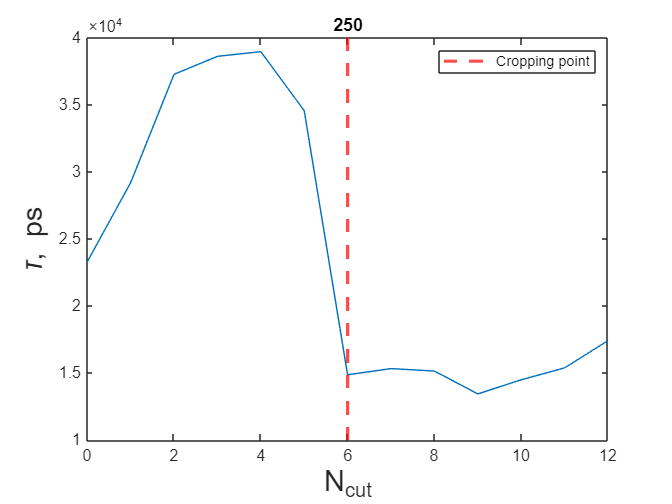

tau_var;

N_cut = 6; % сколько хотим обрезать в итоге

a = 0:1:12;    % проверяли тау для N_cut 0, 1 или 2

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,5])
%ylim([7000,1.3*10^4])

ylabel('\tau, ps','FontSize',18,'FontName','Helvetica')
xlabel('N_{cut}','FontSize',18,'FontName','Helvetica')


%set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

Теперь к начальному участку (слегка отступив от начального момента времени -- t0 -- и до номера итерации, когда происходит видимый выход на экпоенциальную релаксации -- tend) имеет смысл проверить эту кривую в двойных логарифмических коодинатах, т.е. график вида $ln(ln(N_0/N))$ от $ln(t)$ (на это есть причины, опять таки, ниже опишу), и оказыватся, что таки такой выбор переменных дает линеаризацию, т.е. дробно-экспонециальную зависимость от времени

Фактически, зависимость $ln(ln(N_0/N))=A+Bln(t)$ соотвествует дробно-экпоенциальной релаксации $N=N_0\exp(-\lambda_{frac}t^{\mu})$, где $\lambda_{frac}=\exp(A)$, $\mu=B$.

which plot_init_part_ln_ln

C:\Users\anast\AppData\Local\Temp\Editor_bazqk\LiveEditorEvaluationHelperE726993850.m (plot_init_part_ln_ln)  % Local function of LiveEditorEvaluationHelperE726993850


% ln(ln(N/N0)) 

t0 = 22;
tend = 63;
%tend = 30;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.956389042423230


**Параметры прямой для экспоненциального участка:**

N_cut = 6;

tau = tau_var(N_cut+1)

tau =      1.486313322924282e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '250.png'

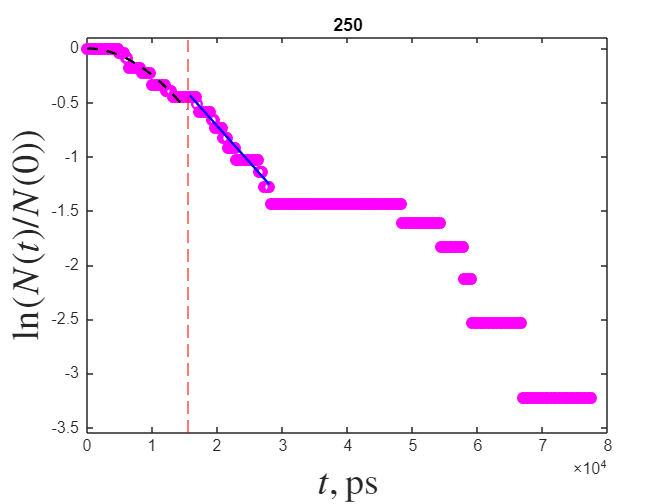

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

% при 250 ничего не обрезала

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

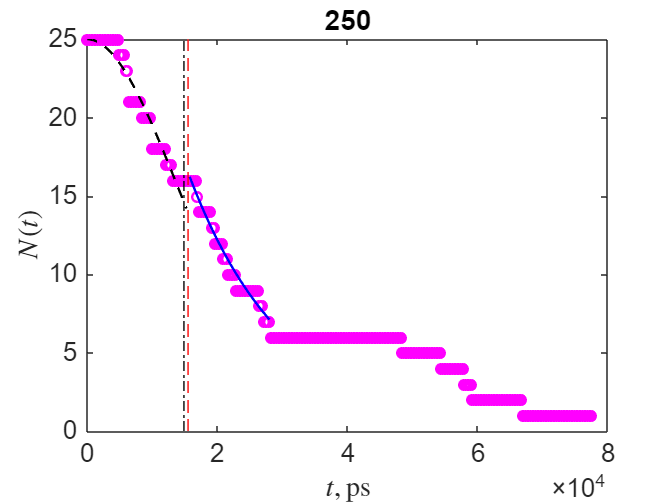


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)

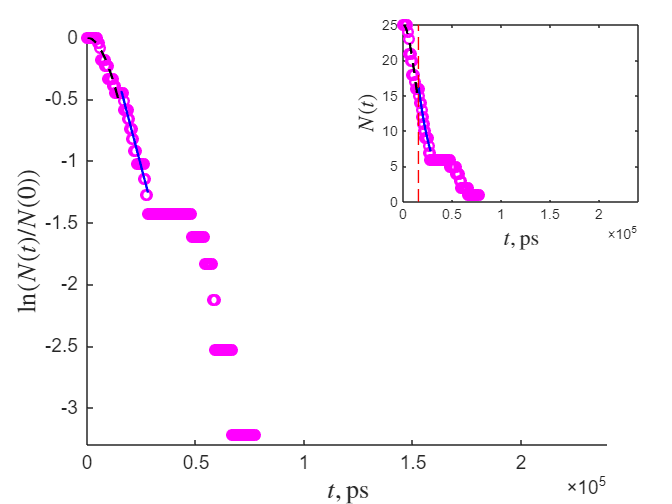


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];


xlim2 = [0,2.4*10^5];
xlim1 = [0,2.4*10^5];
ylim1 = [-3.3,0];
axs = [0.6 0.6 0.35 0.35];
axs1 = [0 0 800 600];

two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

На что следует обратить внимание на графике выше: время экспоненциальной релаксации $\tau=1/\lambda$ как раз примерно совпадает с переходом от горба дробной релаксации к нормальной экспонециальной релаксации (отделено штрих-пунктирной линией), т.е. можно сделать вывод, что при $t<\tau$ там, собственно вообще неравновесный процесс, к нормальной химической кинетике в термодинамическом пределе переход случается как раз на временах, бОльших времени релаксации системы, так что такая двухшаговая зависимость естественна как преход от неравновесной кинетики к равновесной. По этому поводу есть некоторые аналогии, описанные в следующем разделе.

## Некоторые физические соображения и источники

Насколько я понял, читая дипломную работу, сущность $\tau$RAMD предполагает приложения случайной избыточной силы, прикладывамой к лиганду, чтобы за ее счет получить стохастический выброс из исключительно глубокой потенциальной ямы, из которой при ноормальных условиях за время, доступное для MD компонет не выберется. Т.е. по физическому смыслу это -- escape time problem, известная в стохастической кинетике, понятное введние поставновки задачи и базовых результатов, как в случае стандартного случайного процесса, так и аномального есть в

- Dybiec, B., & Sokolov, I. M. (2015). Estimation of the smallest eigenvalue in fractional escape problems: Semi-analytics and fits. Computer Physics Communications, 187, 29-37.  [https://doi.org/10.1016/j.cpc.2014.10.007](https://doi.org/10.1016/j.cpc.2014.10.007)

Кроме того, известно, что для частицы в потенциальной яме, даже если там в принципе система с нормальной термализацией должна быть (а т.к. в этих данных при $t>\tau$ есть выход на экспоненциальную релаксацию, то в термодинамическом пределе там все на обычную химкинетику выходит), но исходно система приготовлена в состоянии, не совпадающим с собственными функциями Фоккера-Планка термодинамизированной системы, возможно существование неспектральных мод, происхождение которых обусловлено начальными условиями, см.

- Toenjes, R., Sokolov, I. M., & Postnikov, E. B. (2013). Nonspectral Relaxation in One Dimensional Ornstein-Uhlenbeck Processes. Physical review letters, 110, 150602. [https://doi.org/10.1103/PhysRevLett.110.150602](https://doi.org/10.1103/PhysRevLett.110.150602)

Более того, показано, что в подобной системе как раз и существует духступенчатый процесс, когда сначала ведущей является неспекральная (аномально-релаксационная) мода, а потом она вымирает и происходит переход на нормальную релаксацию:

- Thiel, F., Sokolov, I. M., & Postnikov, E. B. (2016). Nonspectral modes and how to find them in the Ornstein-Uhlenbeck process with white $\mu$-stable noise. Physical Review E, 93, 052104. [https://doi.org/10.1103/PhysRevE.93.052104](https://doi.org/10.1103/PhysRevE.93.052104)

Т.е. исходный вывод - MD-кривая ведет себя как раз ожидаемой от примененной конструкции способом.

# 263

close all;clc;
format long
load forces_with_pbcatom
force=force263;
force_value = 263; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1);
N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 18000;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

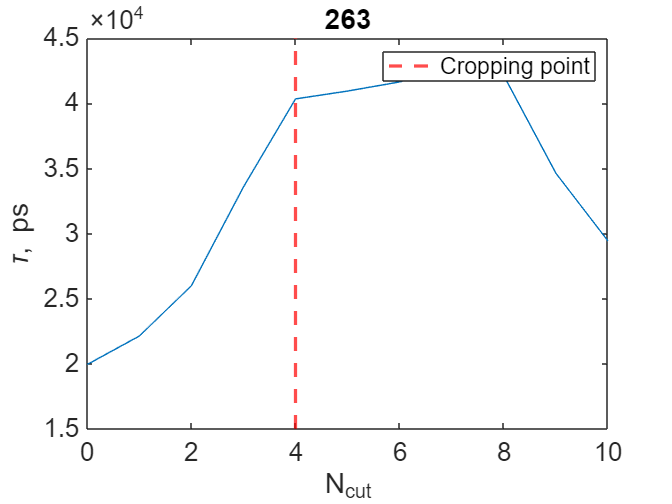

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:10
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 4;

a = 0:1:10;

plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 20;
%tend = 131;
tend = 91;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p;

**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      4.035113289354251e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '263.png'

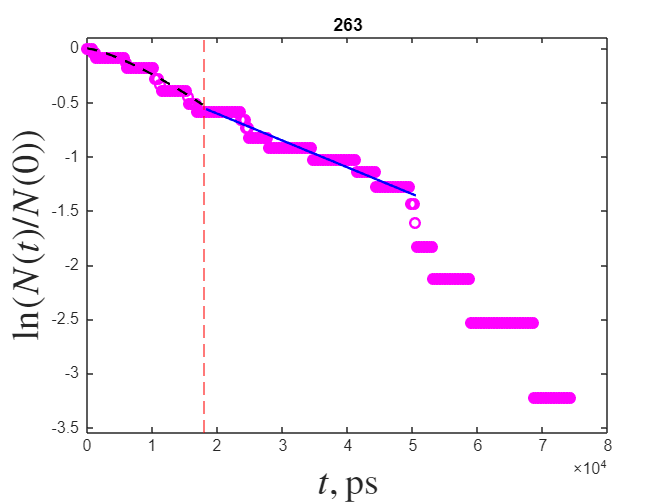

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

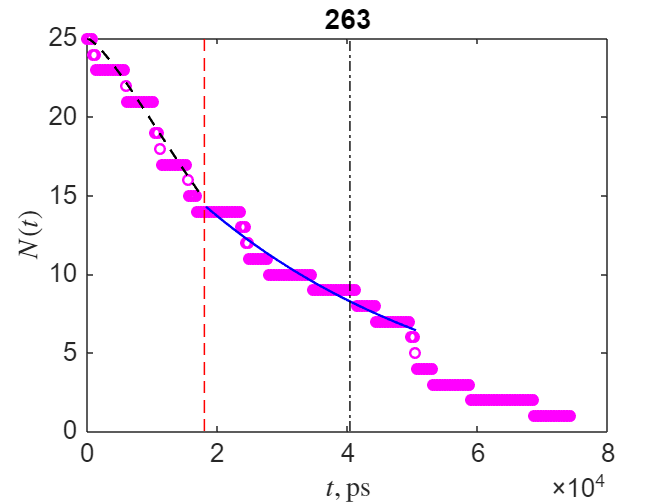


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 275

close all;clc;
format long
load forces_with_pbcatom
force=force275;
force_value = 275; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         400
         800
        1200
        1600
        2000
        2400
        2800
        3200
        3600


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 22800;
%tau_frac = 12000;
tau_frac = 0;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

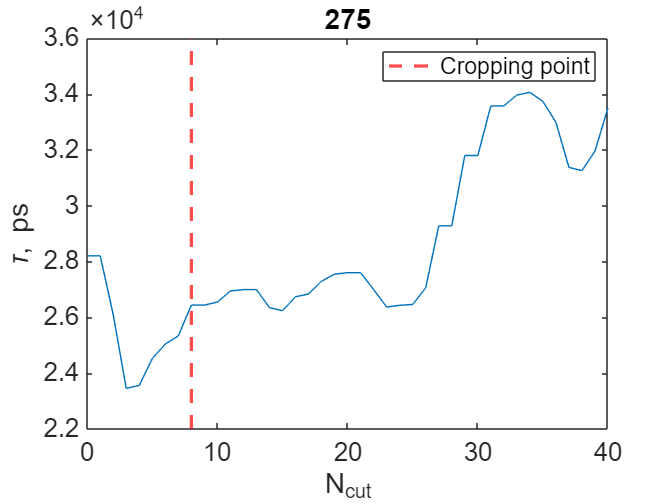

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:40
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 8;

a = 0:1:40;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 10;
tend = 58;
%tend = 31;
%tend = 4

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.084690810978969


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      2.643564323810543e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '275.png'

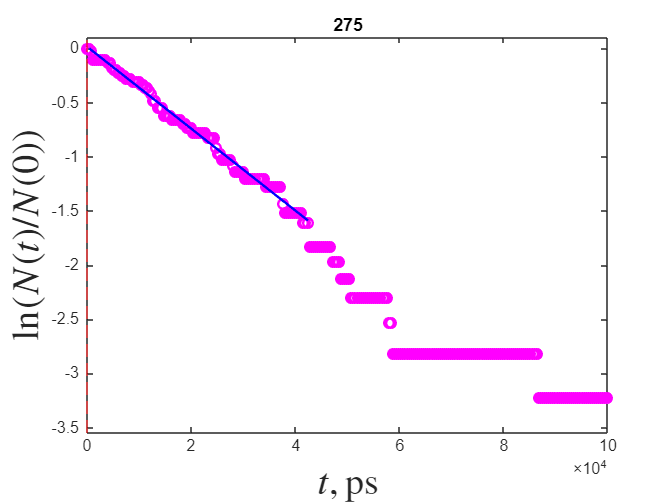

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

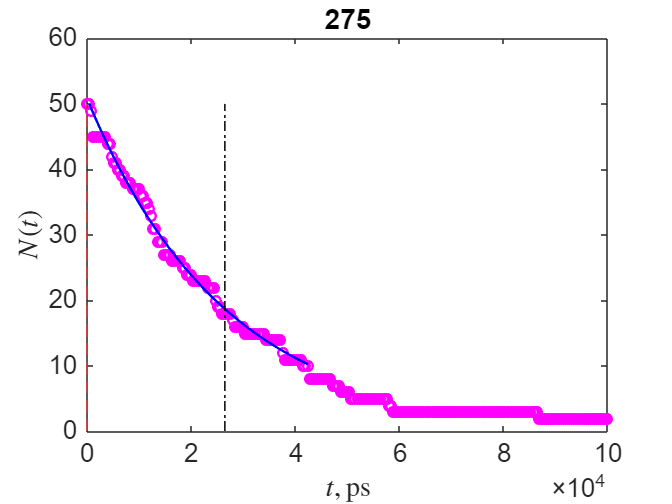


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 288

close all;clc;
format long
load forces_with_pbcatom
force=force288;
force_value = 288; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1);
N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 18000;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

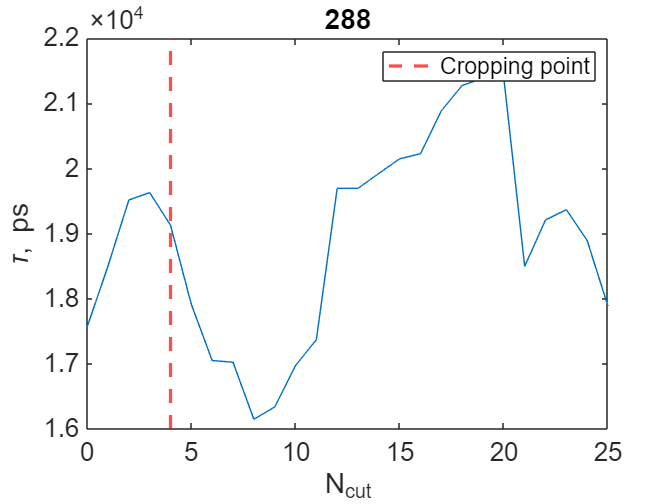

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:25
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 4;

a = 0:1:25;

plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 20;
%tend = 131;
tend = 91;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p;

**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.912803094902381e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '288.png'

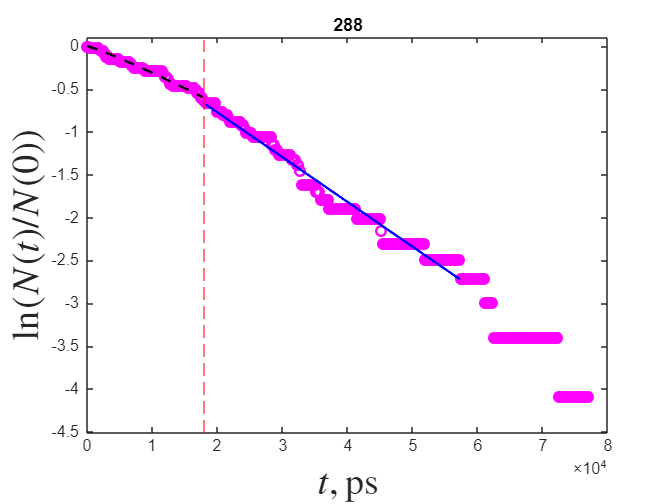

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

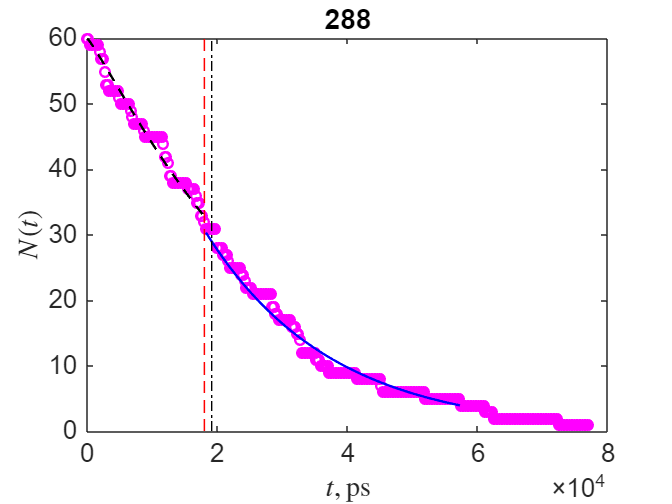


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 300

close all;clc;
format long
load forces_with_pbcatom
force=force300;
force_value = 300; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         250
         500
         750
        1000
        1250
        1500
        1750
        2000
        2250


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 12000;
%tau_frac=13300; 
tau_frac = 0;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);
pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

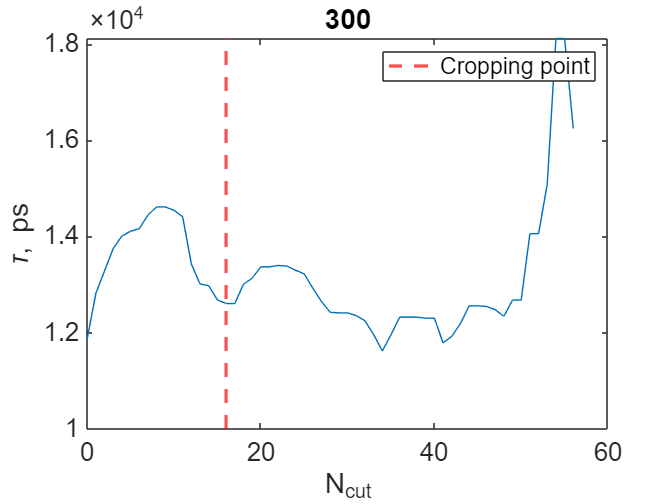

tau_var;

N_cut = 16;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,5])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 3;
tend = 49;
%tend = 20;
%tend = 66;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.026107112412588


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      1.260575985538972e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '300.png'

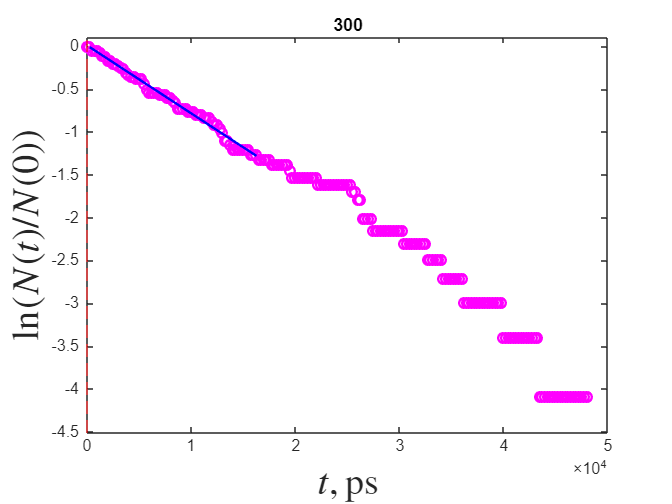

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

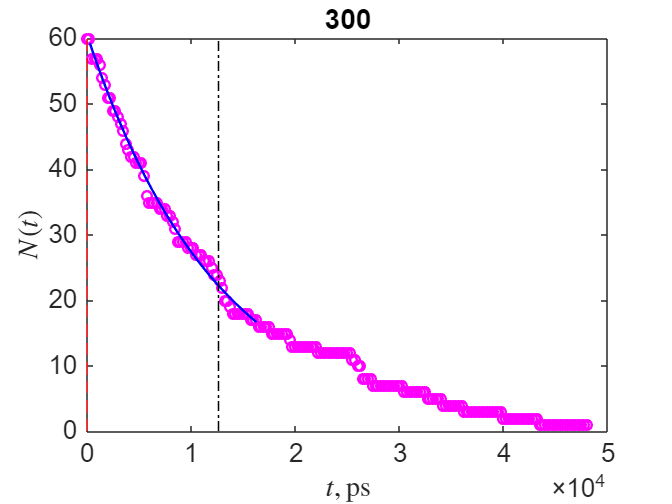


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

% xlim2 = [0,4.3*10^4];
% xlim1 = [0,4.3*10^4];
% ylim1 = [-4,0];
% axs = [0.57 0.57 0.35 0.35];
% 

# 313

close all;clc;
format long
load forces_with_pbcatom
force=force313;
force_value = 313; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         150
         300
         450
         600
         750
         900
        1050
        1200
        1350


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 2550;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

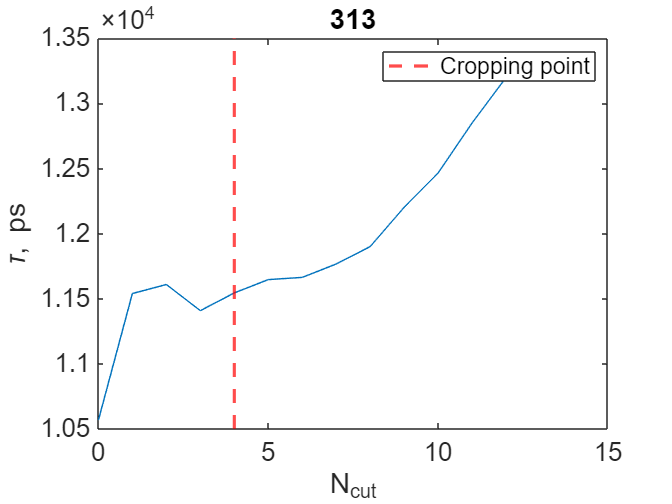

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:13
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 4;

a = 0:1:13;

plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 131;
tend = 18;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p;

**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.154425730052014e+04


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '313.png'

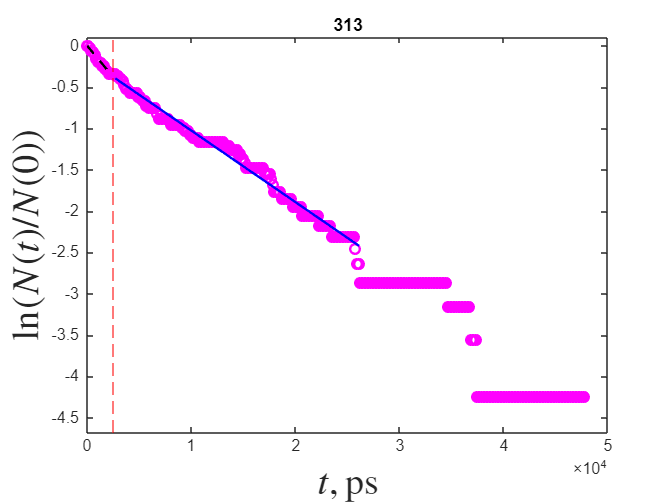

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

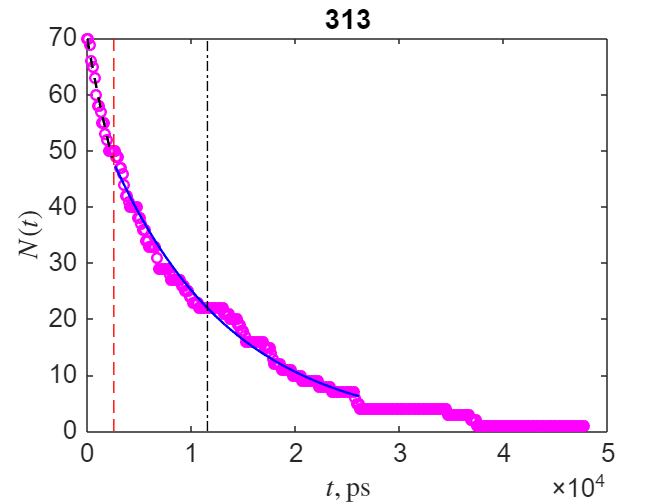


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 325

close all;clc;
format long
load forces_with_pbcatom
force=force325;
force_value = 325; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         150
         300
         450
         600
         750
         900
        1050
        1200
        1350


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

tau_frac = 0;
%tau_frac = 2650;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

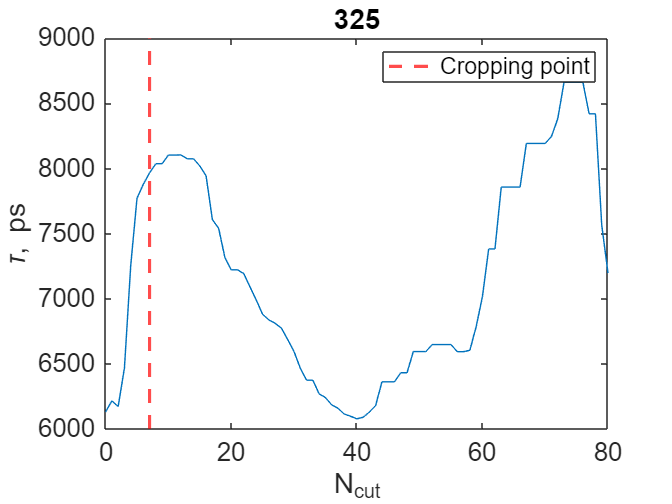

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:80
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 7;

a = 0:1:80;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 20;
tend = 54;
%tend = 73;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    0.940074455463463


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      7.966720344830311e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '325.png'

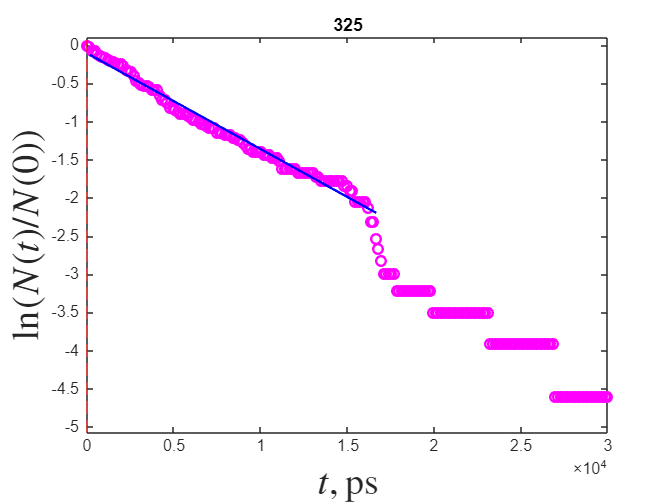

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

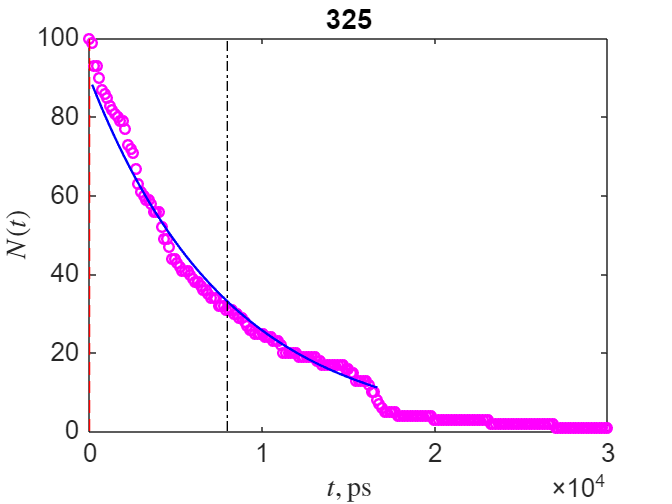


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 338

close all;clc;
format long
load forces_with_pbcatom
force=force338;
force_value = 338; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =            0
         300
         600
         900
        1200
        1500
        1800
        2100
        2400
        2700


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 0;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

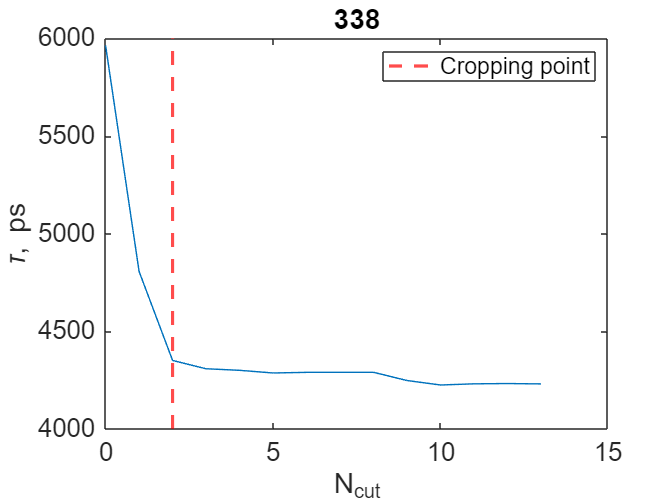

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:13
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 2;

a = 0:1:13;

plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 131;
tend = 5;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p;

**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      4.350221460923820e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '338.png'

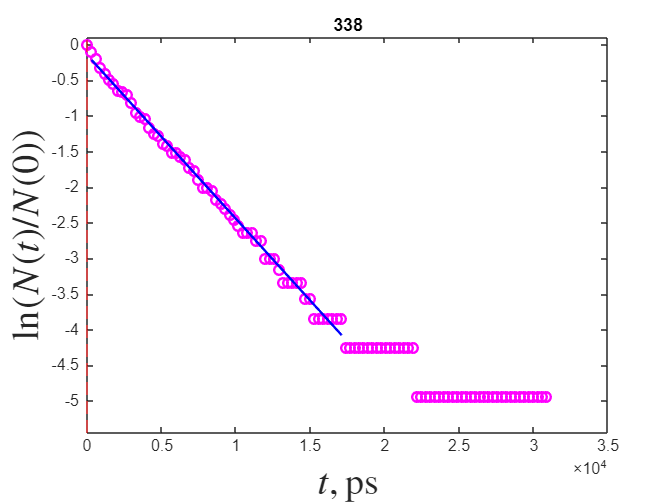

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

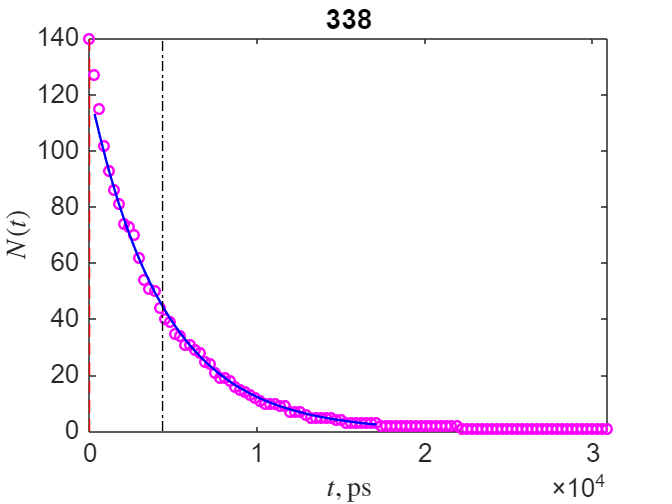


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 350

close all;clc;
format long
load forces_with_pbcatom
force=force350;
force_value = 350; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
   100
   200
   300
   400
   500
   600
   700
   800
   900


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac=2000; 
tau_frac = 1100;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

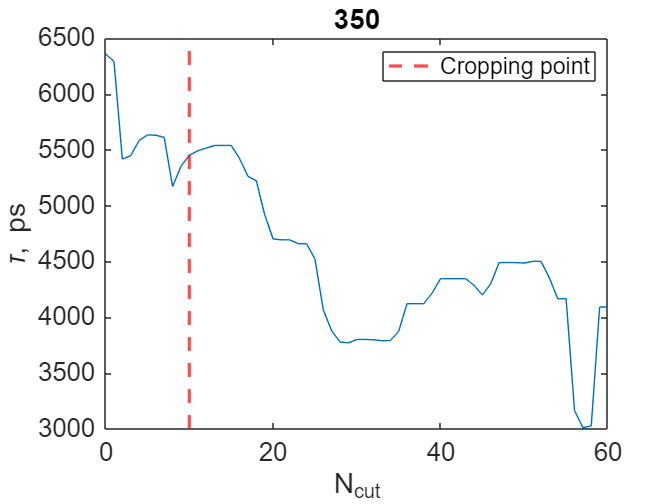

tau_var;

N_cut = 10;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
%vline = plot(N_cut,tau_var(N_cut+1),'.','color','red','Markersize',20);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 2;
%tend = 21;
tend = 12;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.560670950384730


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      5.452894858661981e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '350.png'

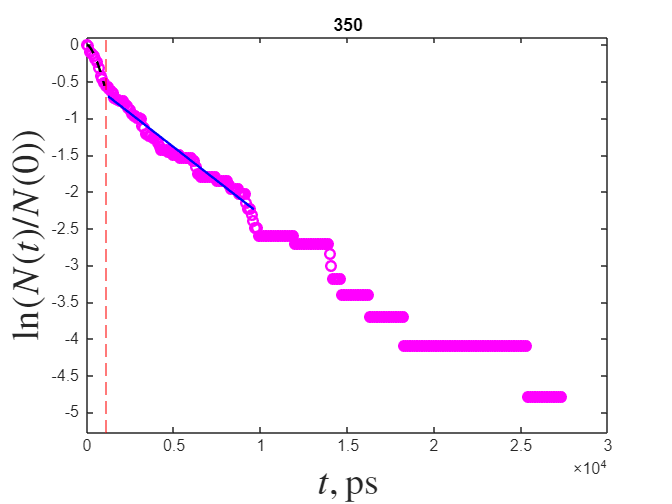

ylim1 = [-5,1];
xlim2 = [0,6200];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

t_fit;
plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

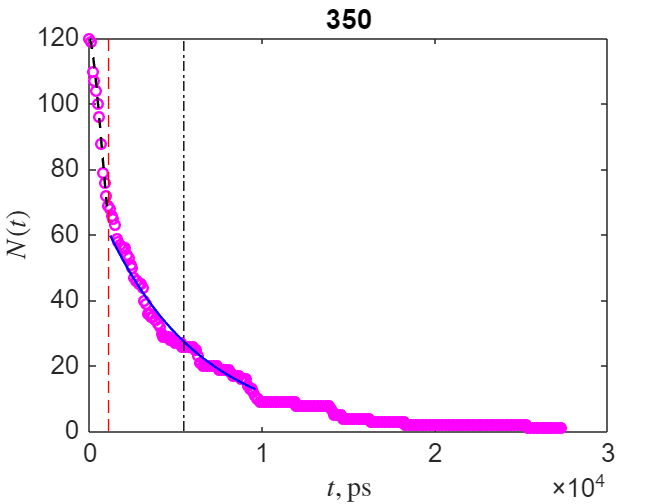


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)




% xlim2 = [0,6200];
% ylim1 = [-4.8,0];
% xlim1 = [0,6500];
% axs = [0.58 0.58 0.34 0.34];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 363

close all;clc;
format long
load forces_with_pbcatom
force=force363;
force_value = 363; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
   100
   200
   300
   400
   500
   600
   700
   800
   900


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac=2000; 
tau_frac = 1100;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:20
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

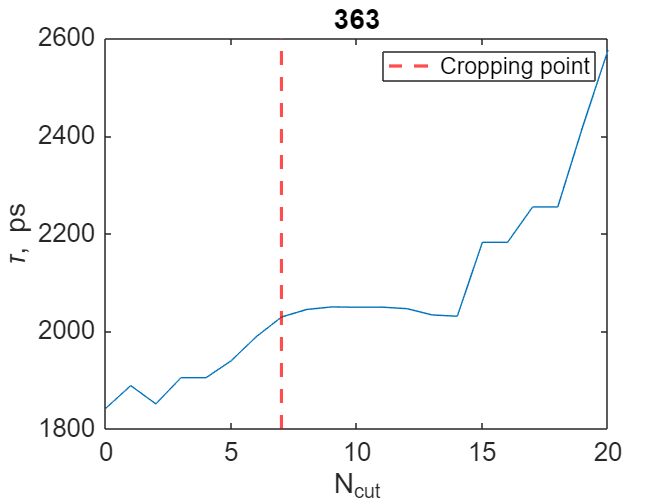

tau_var;

N_cut = 7;

a = 0:1:20;

plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
%vline = plot(N_cut,tau_var(N_cut+1),'.','color','red','Markersize',20);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 3;
%tend = 101;
tend = 12;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p;

**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      2.028969237943086e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '363.png'

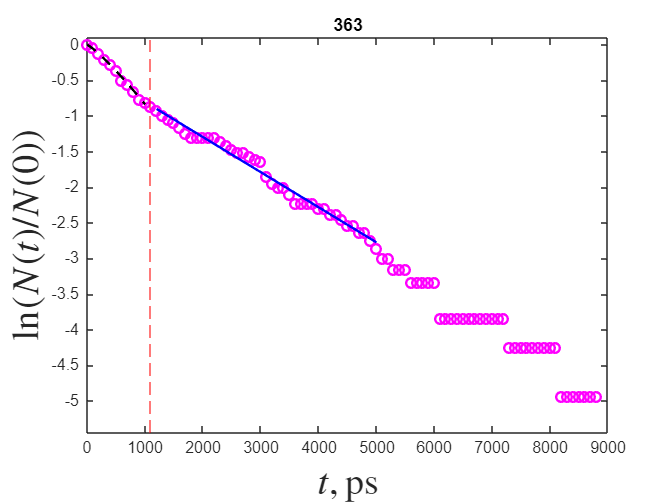

ylim1 = [-5,1];
xlim2 = [0,6200];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

t_fit;
plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

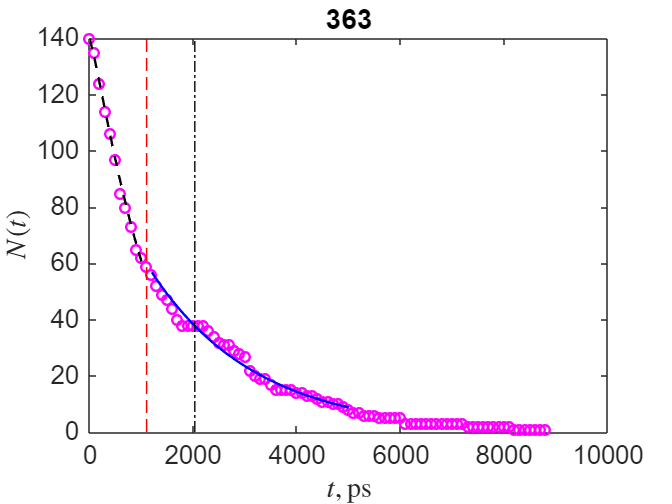


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)




% xlim2 = [0,6200];
% ylim1 = [-4.8,0];
% xlim1 = [0,6500];
% axs = [0.58 0.58 0.34 0.34];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 375

close all;clc;
format long
load forces_with_pbcatom
force=force375;
force_value = 375; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
    30
    60
    90
   120
   150
   180
   210
   240
   270


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 630;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

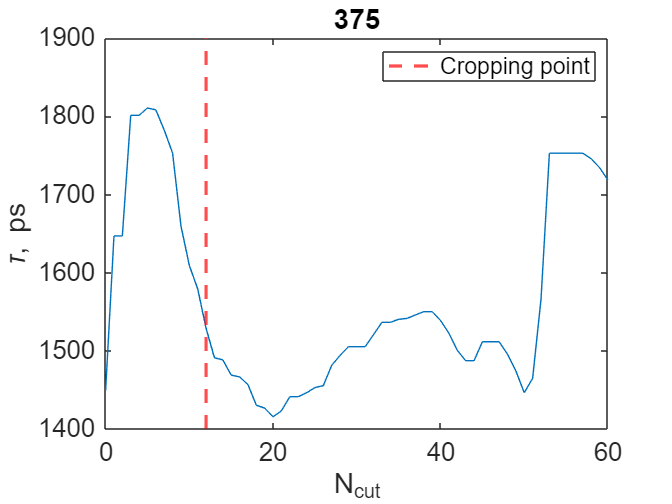

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 12;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 2;
%tend = 131;
tend = 22;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.129872531921447


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.528695447123812e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '375.png'

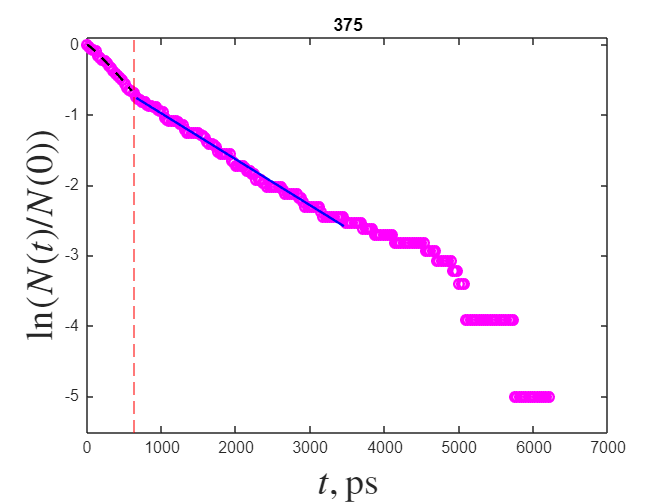

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

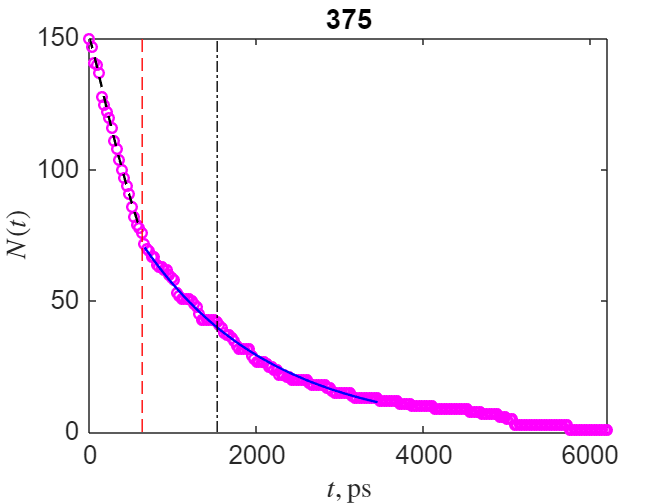


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 388

close all;clc;
format long
load forces_with_pbcatom
force=force388;
force_value = 388; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
    50
   100
   150
   200
   250
   300
   350
   400
   450


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 630;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

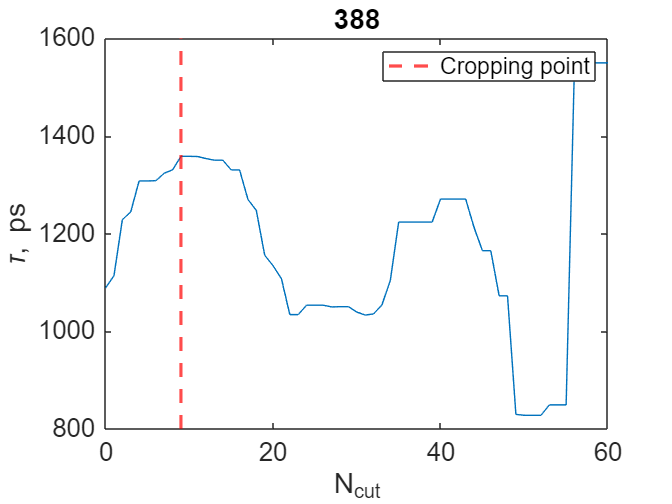

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 9;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 2;
%tend = 131;
tend = 22;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.083488137849318


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.358374073904351e+03


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '388.png'

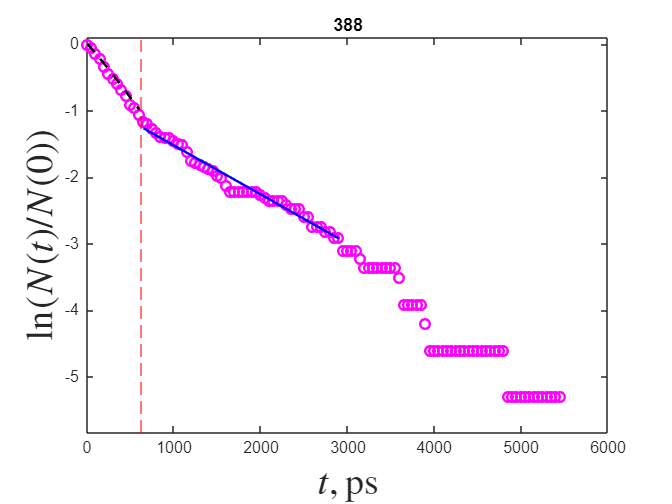

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

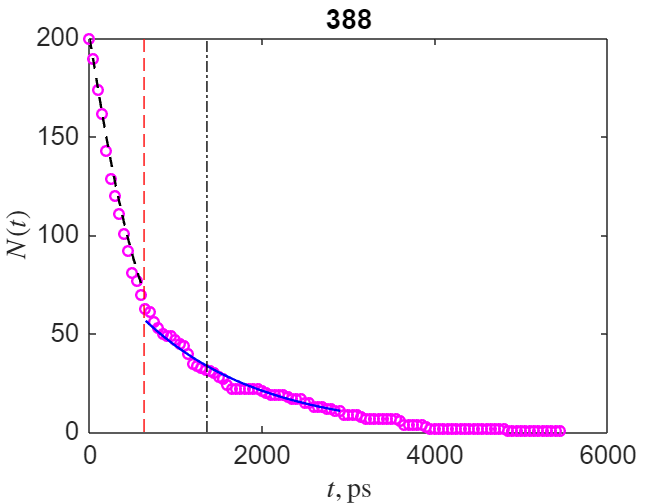


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 400

close all;clc;
format long
load forces_with_pbcatom
force=force400;
force_value = 400; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
    20
    40
    60
    80
   100
   120
   140
   160
   180


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac=500;
%tau_frac = 440;
tau_frac = 480;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

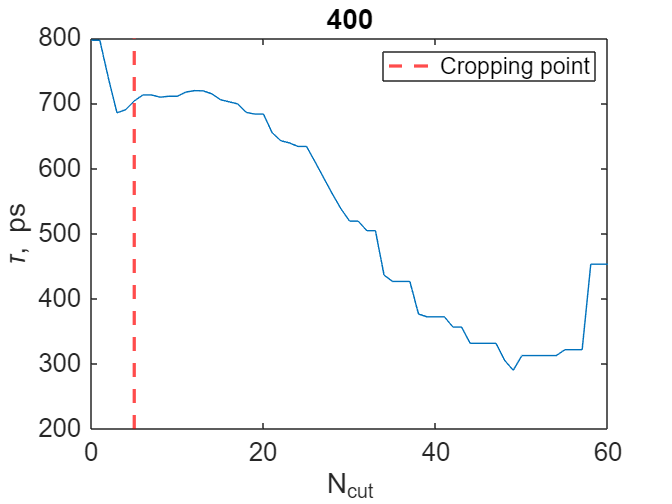

tau_var;

N_cut = 5;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 51;
%tend = 45;
tend = 25;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.206113336241856


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      7.038764794559174e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '400.png'

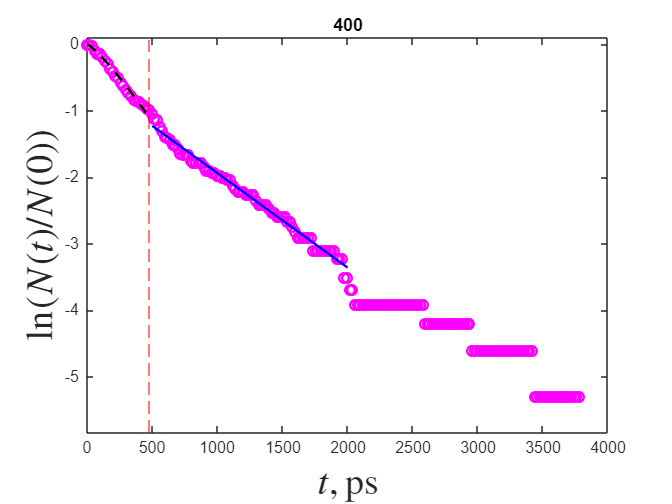

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

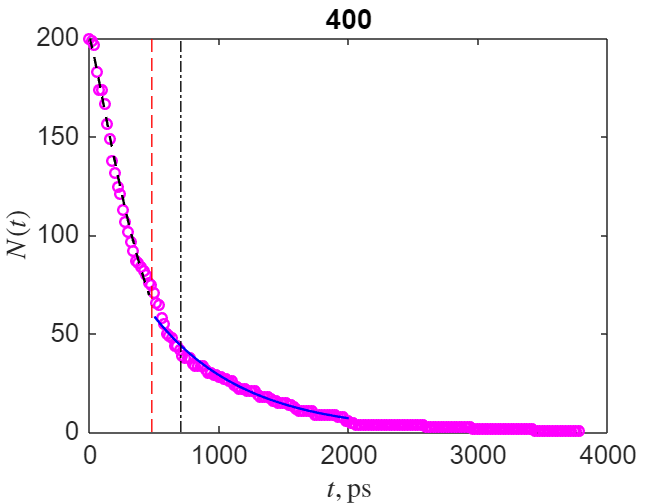


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 413

close all;clc;
format long
load forces_with_pbcatom
force=force413;
force_value = 413; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
    20
    40
    60
    80
   100
   120
   140
   160
   180


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac=500;
%tau_frac = 440;
tau_frac = 480;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:20
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

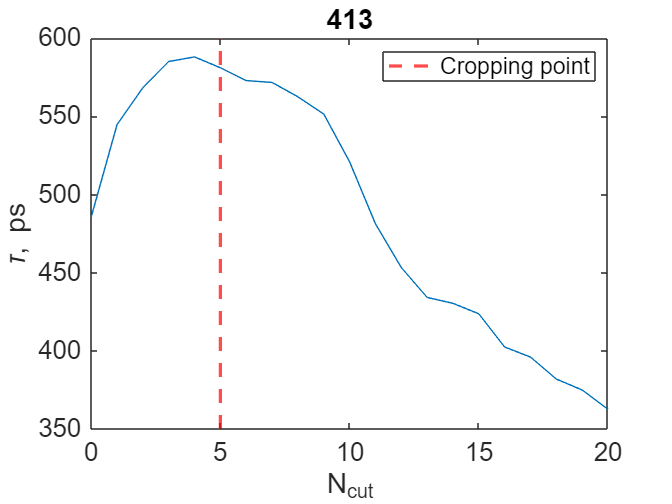

tau_var;

N_cut = 5;

a = 0:1:20;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 51;
%tend = 45;
tend = 25;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.002718999294880


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      5.811654512664921e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '413.png'

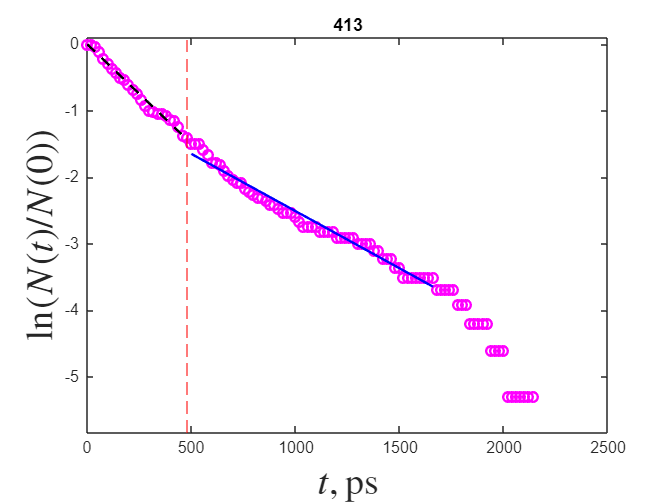

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

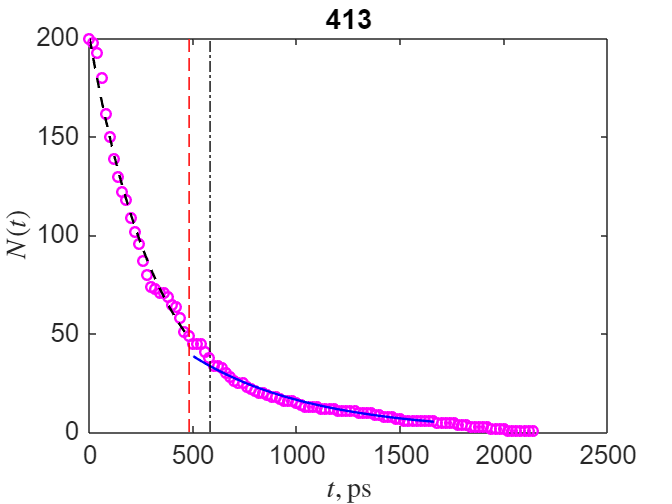


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 425

close all;clc;
format long
load forces_with_pbcatom
force=force425;
force_value = 425; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
    10
    20
    30
    40
    50
    60
    70
    80
    90


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 210;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

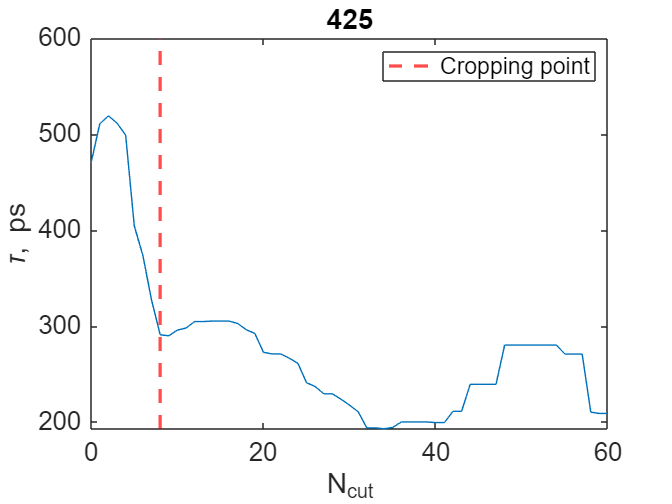

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 8;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 131;
tend = 22;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.253084549838831


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      2.909212927605253e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '425.png'

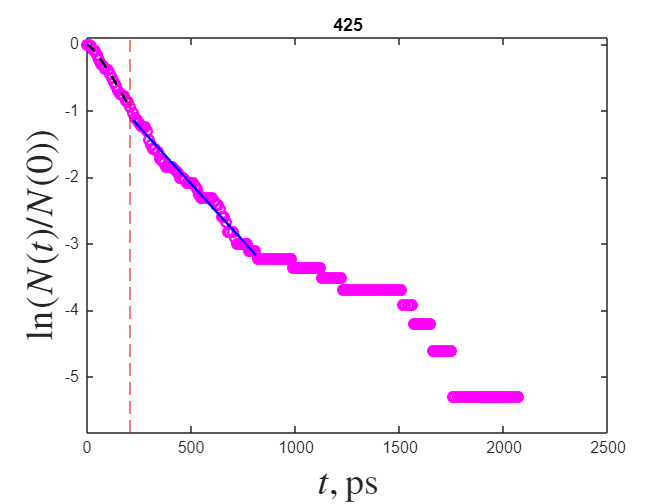

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

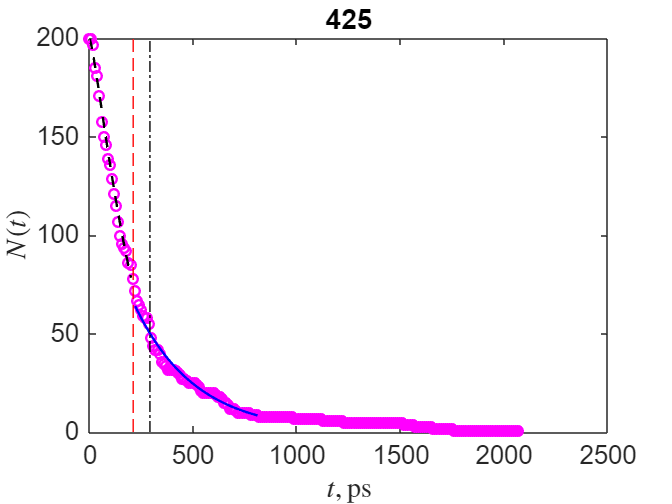


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 438

close all;clc;
format long
load forces_with_pbcatom
force=force438;
force_value = 438; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     7
    14
    21
    28
    35
    42
    49
    56
    63


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 105;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

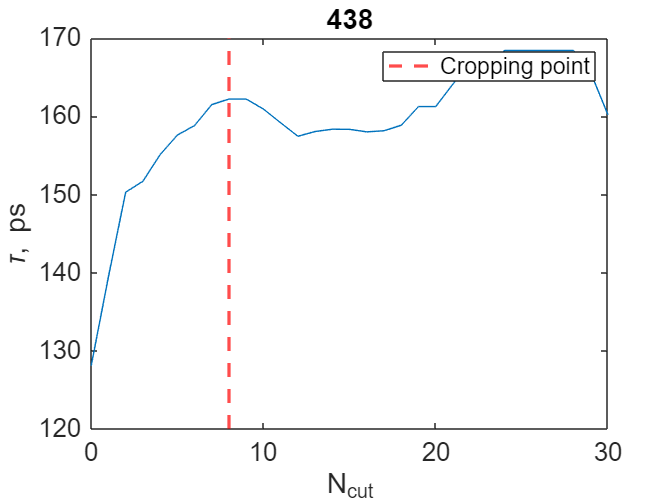

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:30
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 8;

a = 0:1:30;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 131;
tend = 16;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.680659587120079


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.622316035381462e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '438.png'

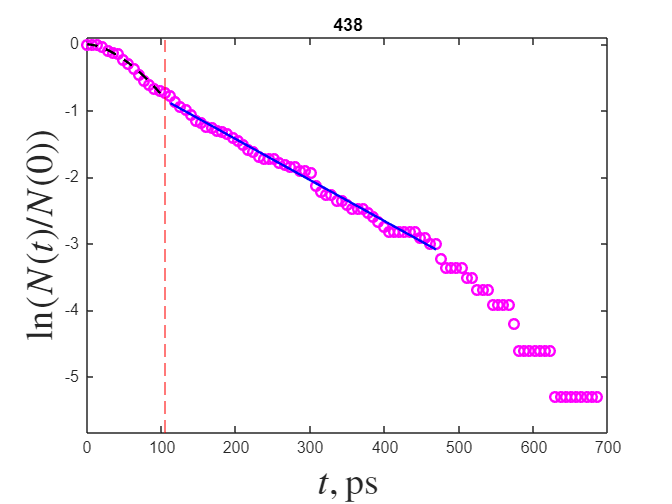

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

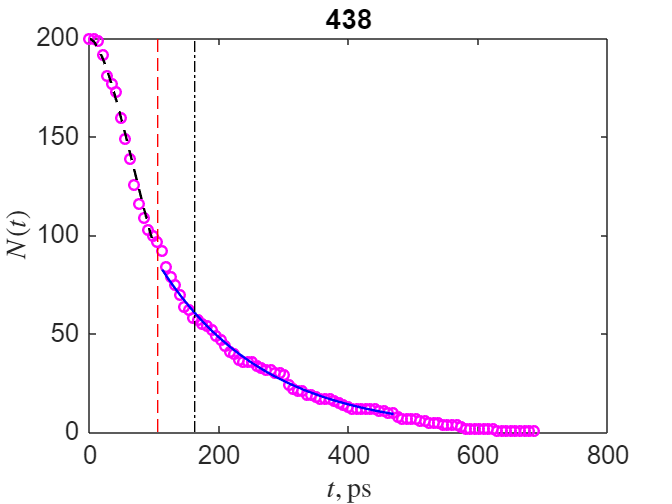


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];

%two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value];
tau_all = [tau_all, tau];

# 450

close all;clc;
format long
load forces_with_pbcatom
force=force450;
force_value = 450; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     4
     8
    12
    16
    20
    24
    28
    32
    36


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 170;
%tau_frac=240; 
tau_frac = 80;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end


**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

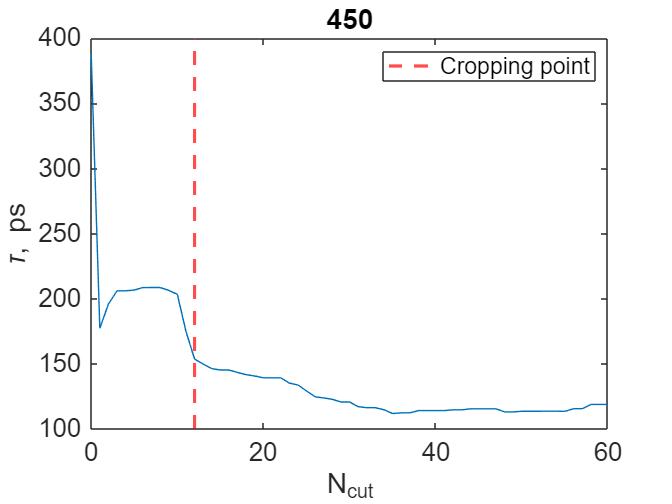

tau_var;

N_cut = 12; %сколько обрезается

a = 0:1:60;


figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 86;
%tend = 121;
tend = 21;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    2.230449017719994


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =      1.536362864053331e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '450.png'

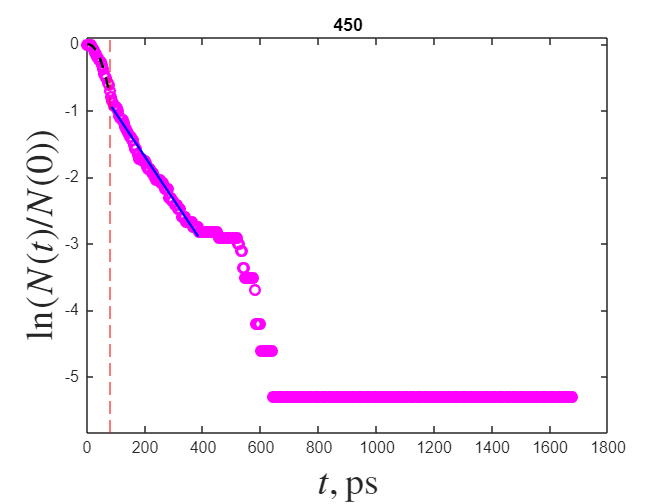

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

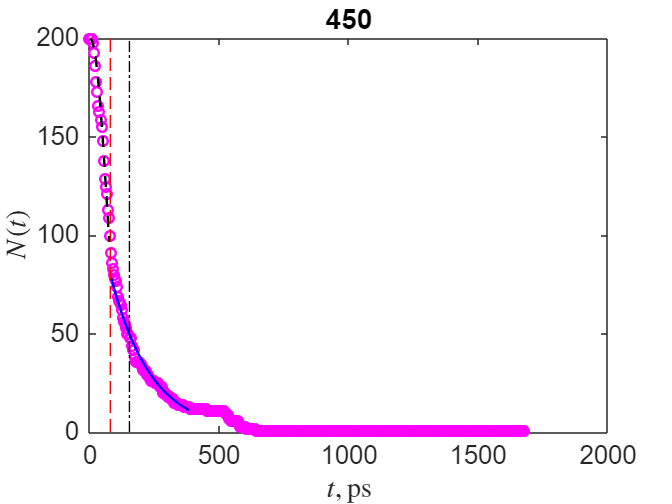


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)



% xlim2 = [0,800];
% ylim1 = [-6,0];
% xlim1 = [0,800];
% axs = [0.57 0.57 0.35 0.35];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 463

close all;clc;
format long
load forces_with_pbcatom
force=force463;
force_value = 463; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     4
     8
    12
    16
    20
    24
    28
    32
    36


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 170;
%tau_frac=240; 
tau_frac = 80;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end


**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

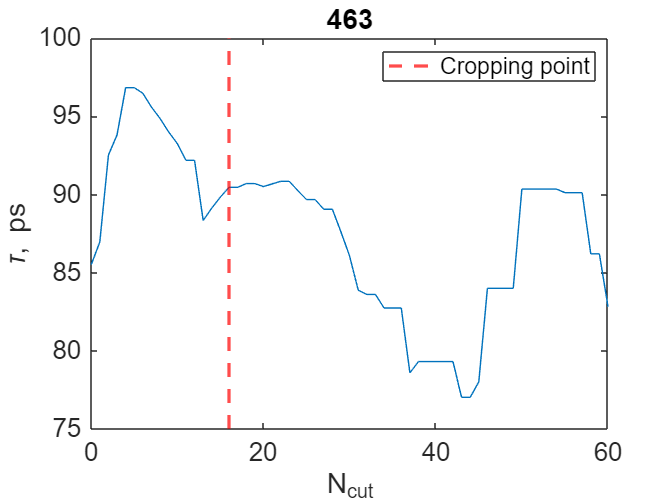

tau_var;

N_cut = 16; %сколько обрезается

a = 0:1:60;


figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 86;
%tend = 121;
tend = 21;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    2.314697043144308


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =   90.464741753149113


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '463.png'

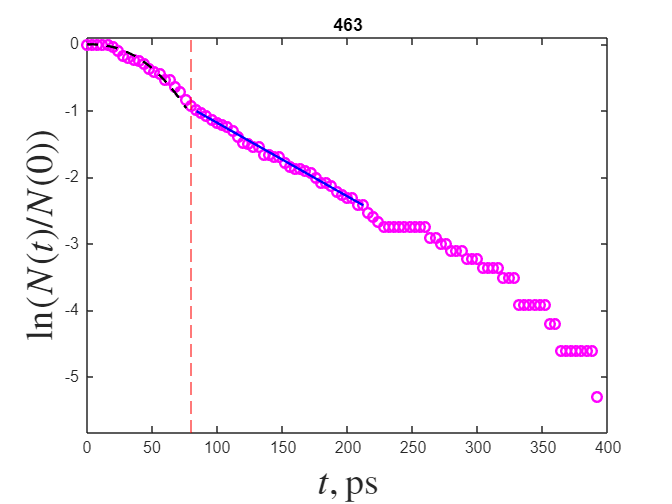

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

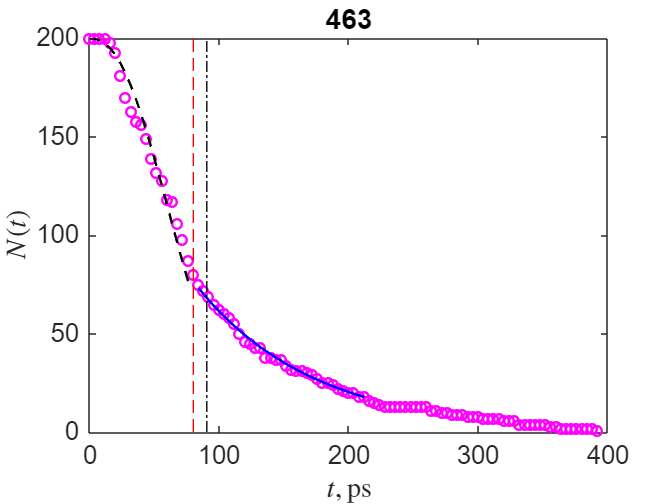


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)



% xlim2 = [0,800];
% ylim1 = [-6,0];
% xlim1 = [0,800];
% axs = [0.57 0.57 0.35 0.35];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 475

close all;clc;
format long
load forces_with_pbcatom
force=force475;
force_value = 475; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     5
    10
    15
    20
    25
    30
    35
    40
    45


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 125;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

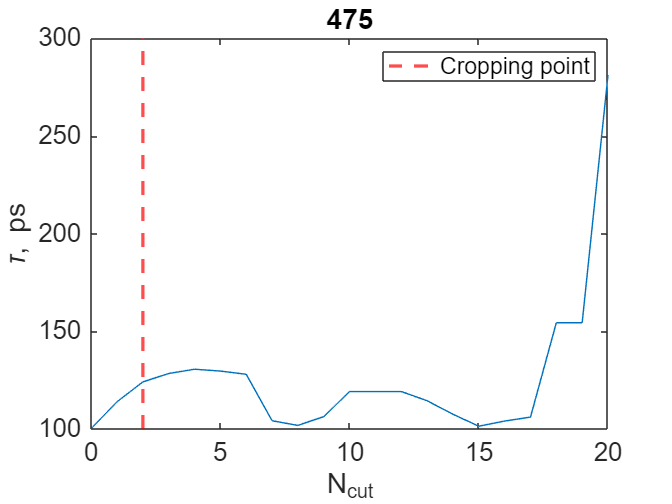

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:20
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 2;

a = 0:1:20;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
tend = 26;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.822519493072052


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =      1.240387635044017e+02


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '475.png'

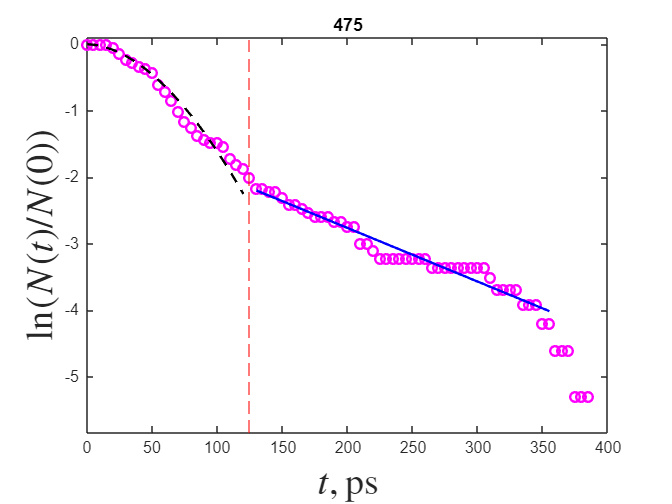

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

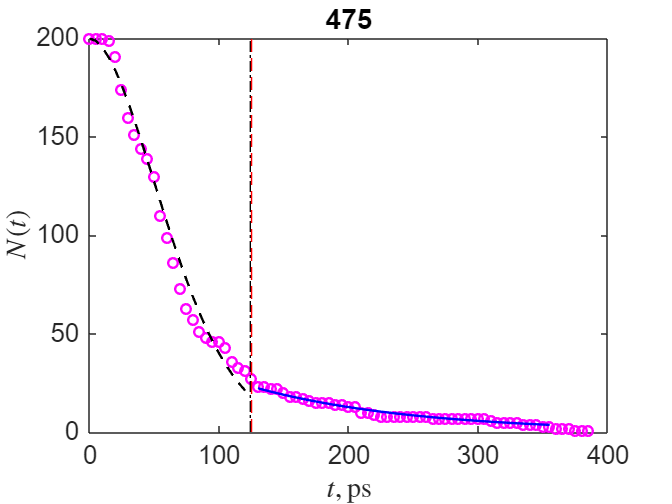


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 488

close all;clc;
format long
load forces_with_pbcatom
force=force488;
force_value = 488; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     2
     4
     6
     8
    10
    12
    14
    16
    18


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 84;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

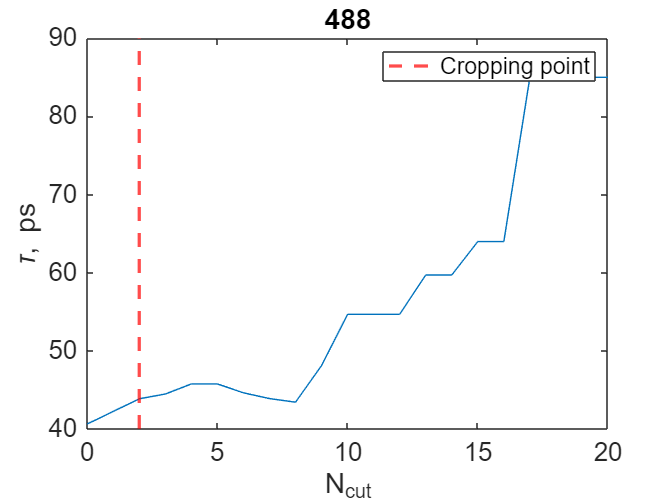

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:20
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 2;

a = 0:1:20;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
tend = 43;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    NaN


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =   43.842754744660269


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '488.png'

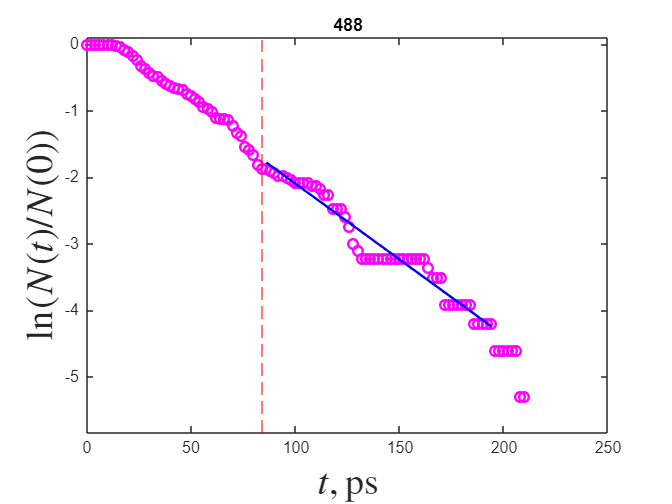

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

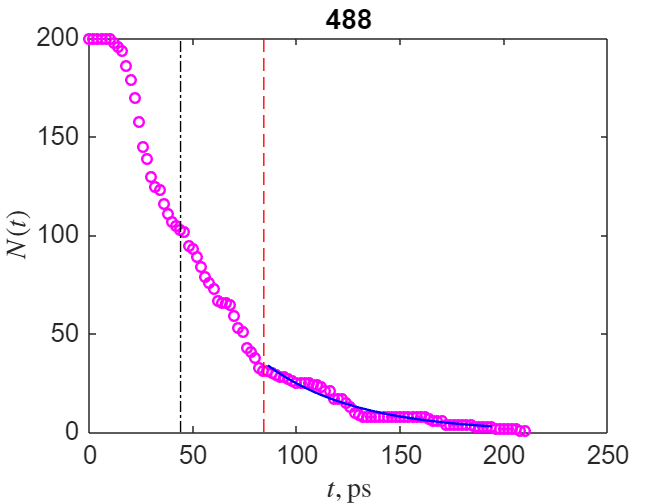


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 500

close all;clc;
format long
load forces_with_pbcatom
force=force500;
force_value = 500; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     3
     6
     9
    12
    15
    18
    21
    24
    27


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 80;
tau_frac=84; 
%tau_frac = 100;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:40
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

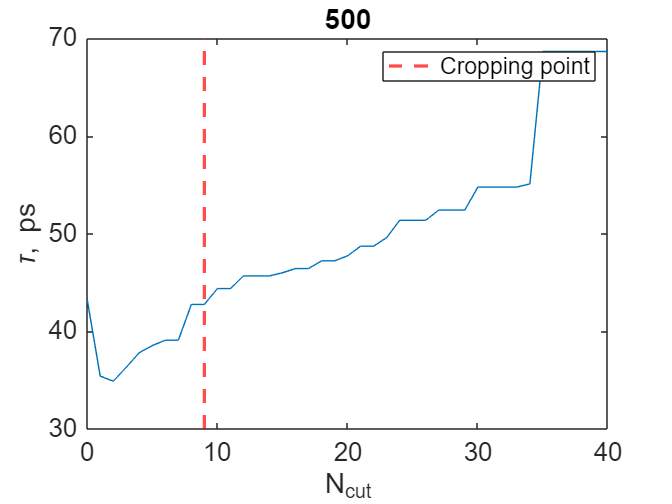

tau_var;

N_cut = 9;

a = 0:1:40;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 5;
%tend = 81;
tend = 29;
%tend = 101;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    1.920814669518140


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =   42.746848070845850


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '500.png'

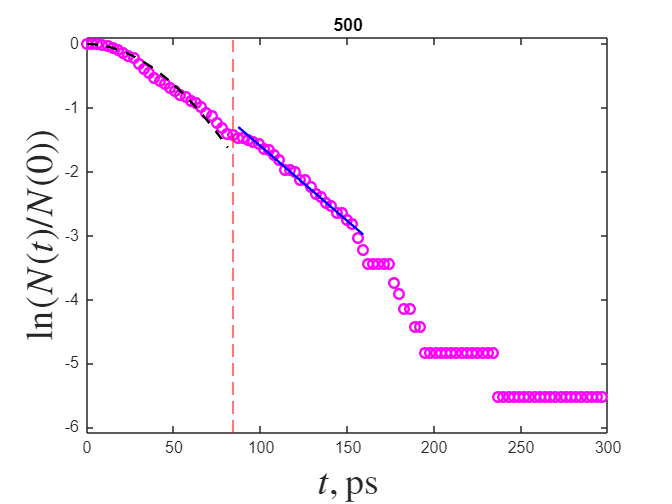

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

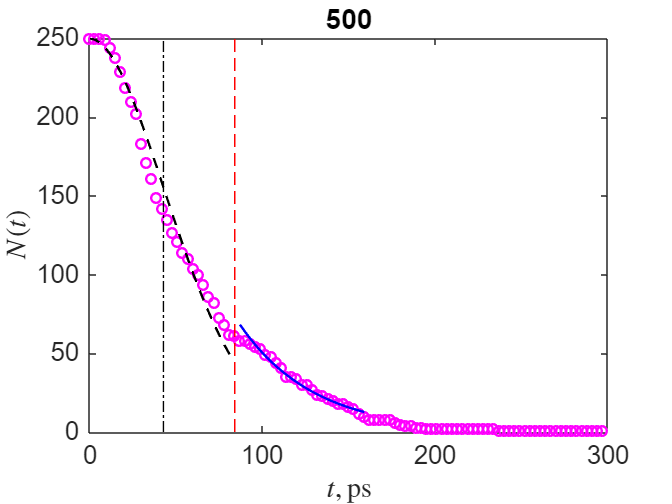


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)





% xlim2 = [0,350];
% ylim1 = [-6,0];
% xlim1 = [0,400];
% axs = [0.57 0.57 0.35 0.35];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 513

close all;clc;
format long
load forces_with_pbcatom
force=force513;
force_value = 513; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     2
     4
     6
     8
    10
    12
    14
    16
    18


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 80;
%tau_frac=62; 
tau_frac = 90;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:6
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau

**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

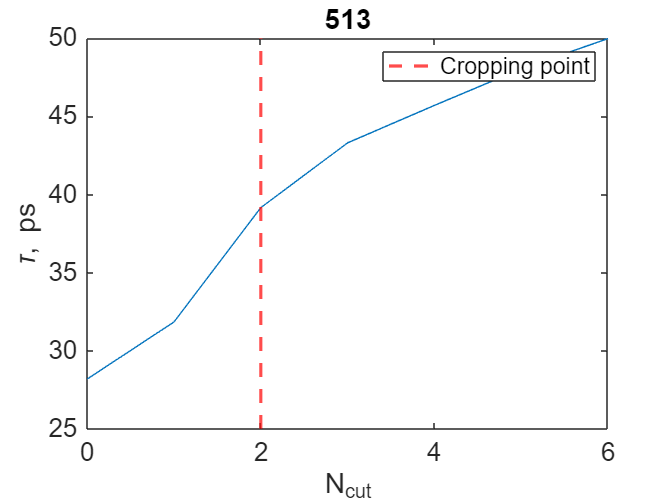

tau_var;

N_cut = 2;

a = 0:1:6;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 10;
%tend = 81;
%tend = 32;
tend = 46;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    2.027719626178800


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =   39.164528587785249


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '513.png'

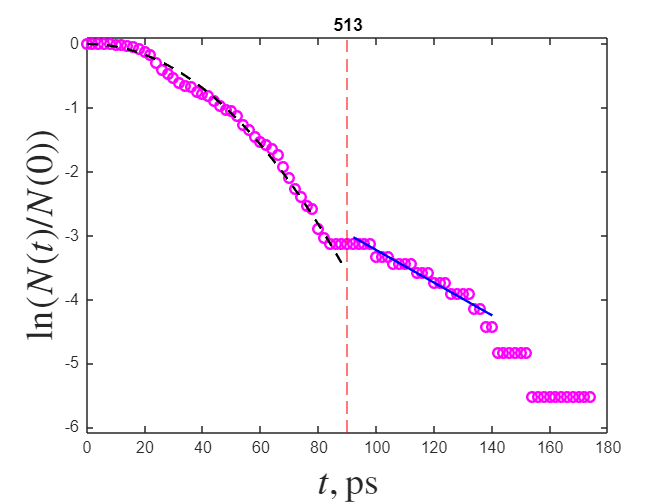

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

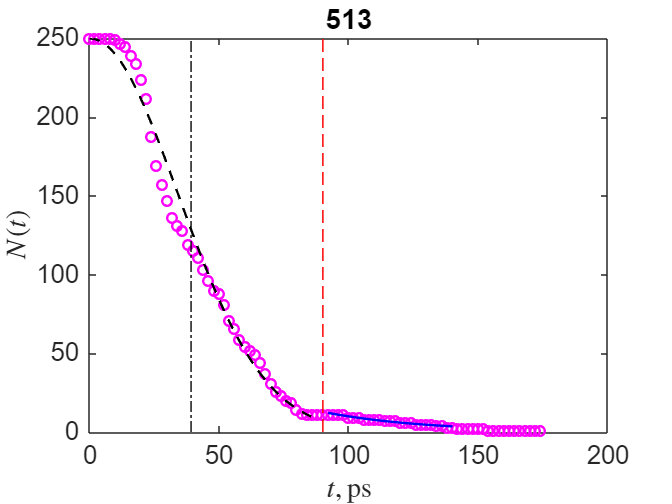


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)





% xlim2 = [0,350];
% ylim1 = [-6,0];
% xlim1 = [0,400];
% axs = [0.57 0.57 0.35 0.35];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 525

close all;clc;
format long
load forces_with_pbcatom
force=force525;
force_value = 525; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     2
     4
     6
     8
    10
    12
    14
    16
    18


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 24;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

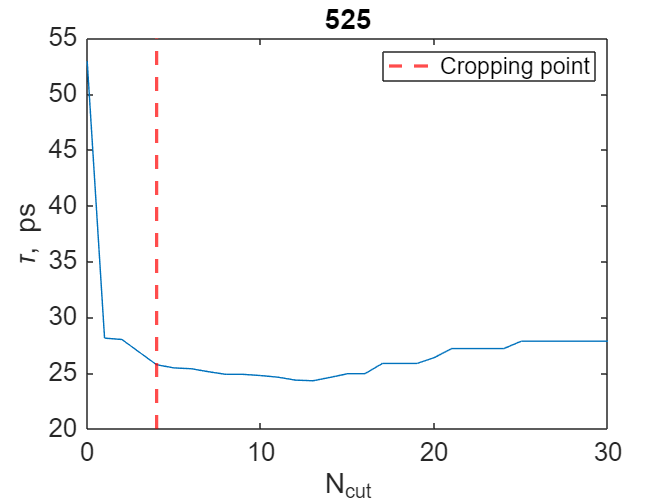

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:30
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 4;

a = 0:1:30;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 6;
tend = 13;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    4.351185214620518


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =   25.739624103436785


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '525.png'

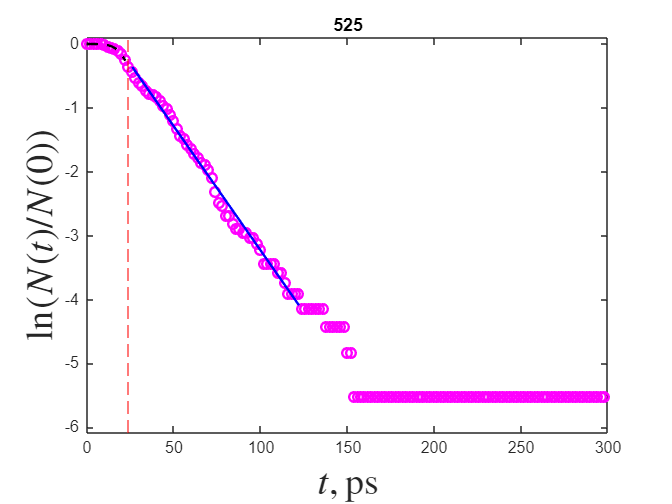

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

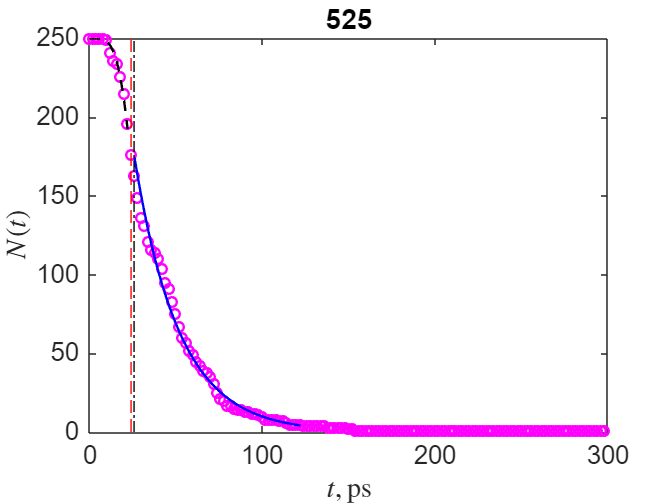


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 538

close all;clc;
format long
load forces_with_pbcatom
force=force538;
force_value = 538; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 37;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

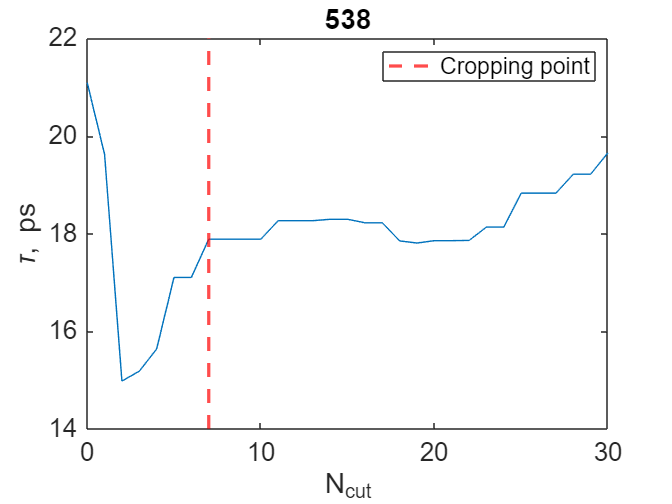

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:30
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 7;

a = 0:1:30;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 6;
tend = 38;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    NaN


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =   17.885585310533791


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '538.png'

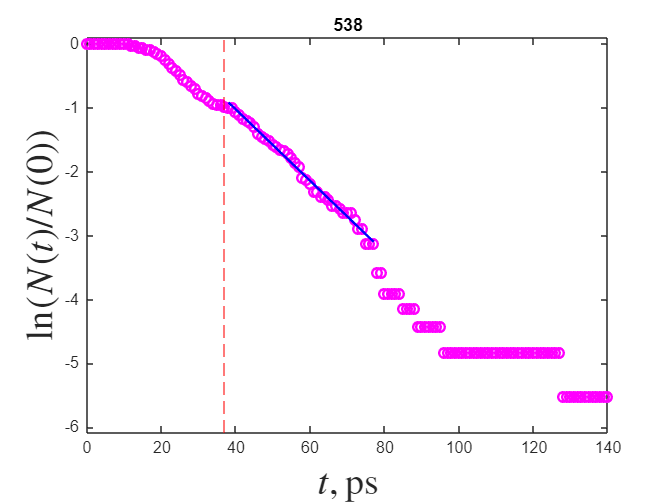

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

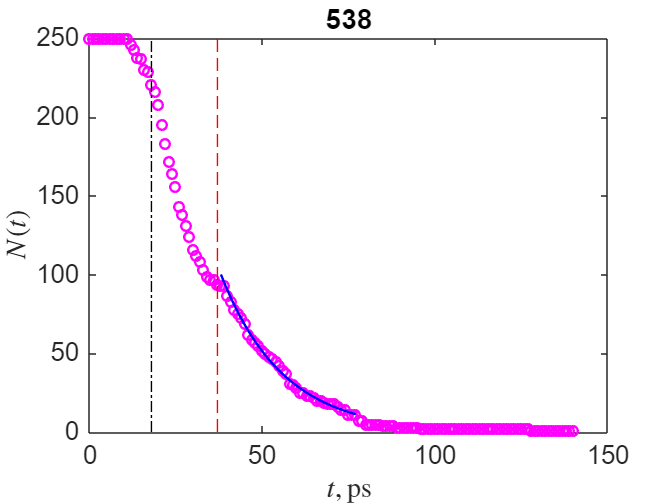


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 550

close all;clc;
format long
load forces_with_pbcatom
force=force550;
force_value = 550; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

tau_frac = 28;
%tau_frac = 21;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:60
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end


**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

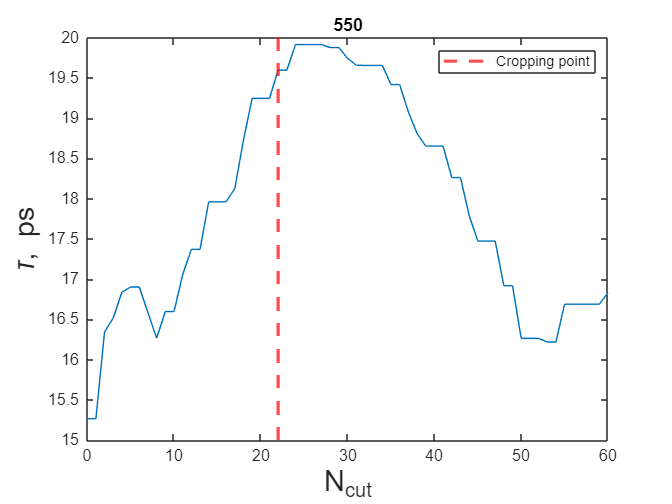

tau_var;

N_cut = 22;

a = 0:1:60;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,5])
%ylim([7000,1.3*10^4])

ylabel('\tau, ps','FontSize',18,'FontName','Helvetica')
xlabel('N_{cut}','FontSize',18,'FontName','Helvetica')

%set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 12;
tend = 29;
%tend = 22;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    4.046069816453739


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =   19.595925520936873


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '550.png'

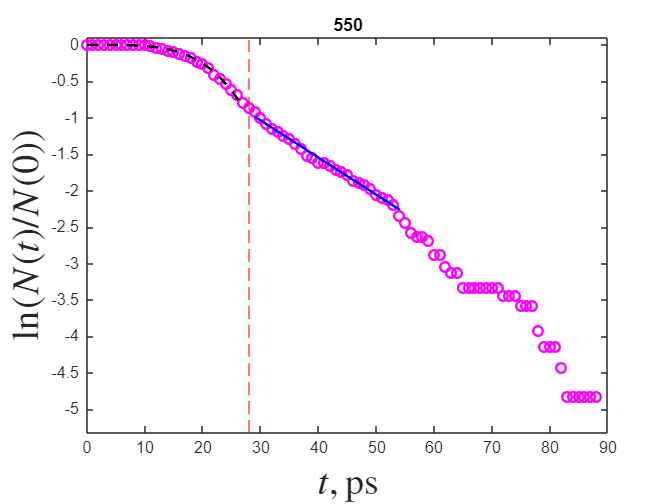

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

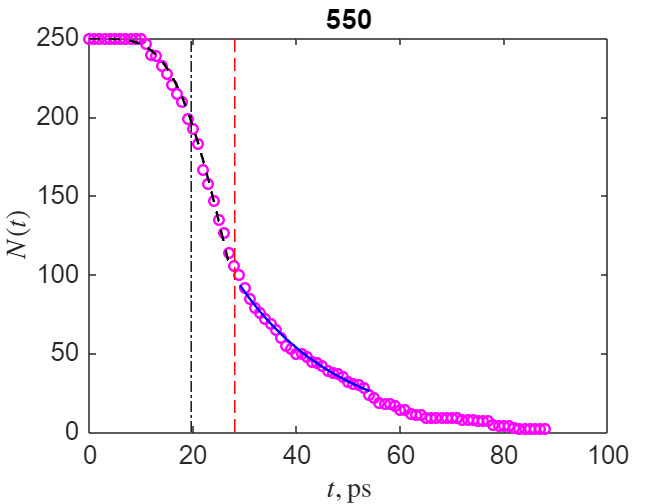


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)



% xlim2 = [0,220];
% ylim1 = [-6,0];
% xlim1 = [0,230];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 563

close all;clc;
format long
load forces_with_pbcatom
force=force563;
force_value = 563; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

tau_frac = 28;
%tau_frac = 21;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 1:30
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end


**Значения тау, если по-разному обрезать (N_cut+1 элемент этого списка значит, что обрезали N_cut):**

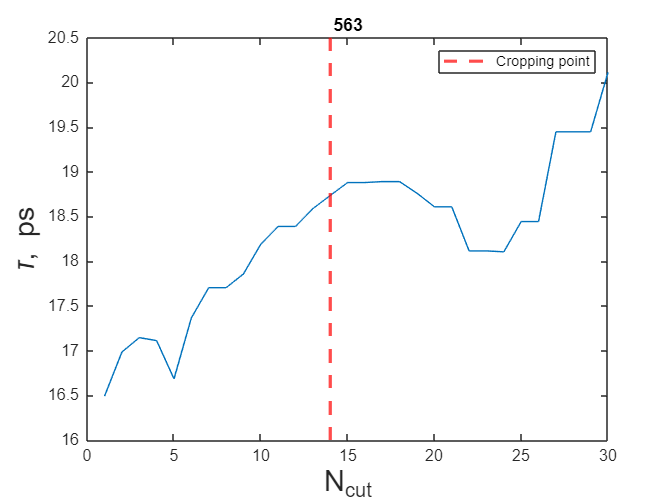

tau_var;

N_cut = 14;

a = 1:1:30;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,5])
%ylim([7000,1.3*10^4])

ylabel('\tau, ps','FontSize',18,'FontName','Helvetica')
xlabel('N_{cut}','FontSize',18,'FontName','Helvetica')

%set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 12;
tend = 29;
%tend = 22;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    3.576865370848215


**Параметры прямой для экспоненциального участка:**

tau = tau_var(N_cut+1)

tau =   18.879225289016624


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '563.png'

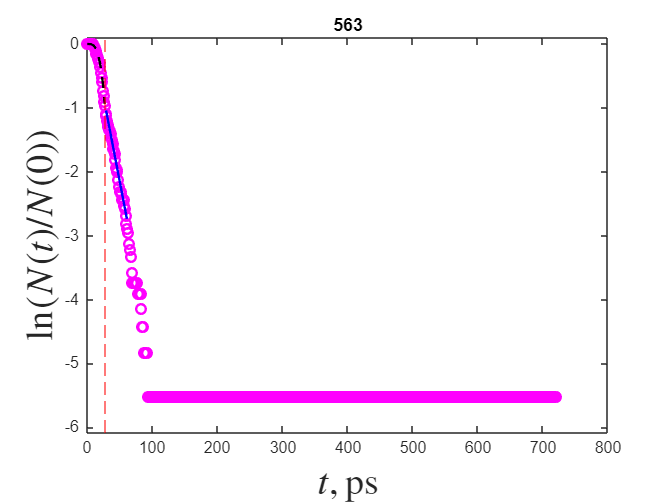

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

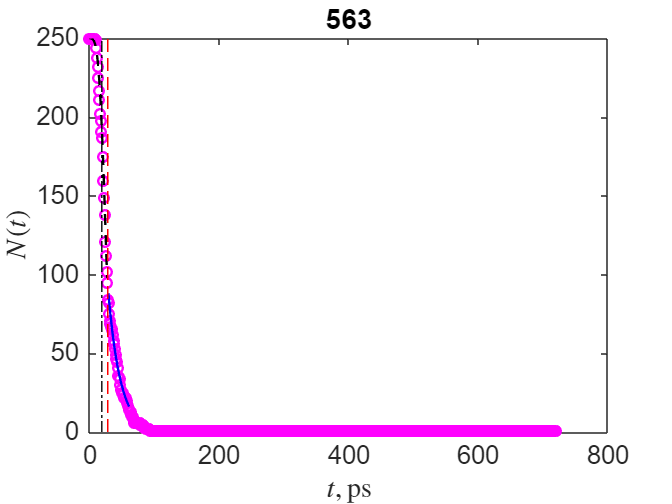


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)



% xlim2 = [0,220];
% ylim1 = [-6,0];
% xlim1 = [0,230];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 575

close all;clc;
format long
load forces_with_pbcatom
force=force575;
force_value = 575; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 25;
%tau_frac = 50;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

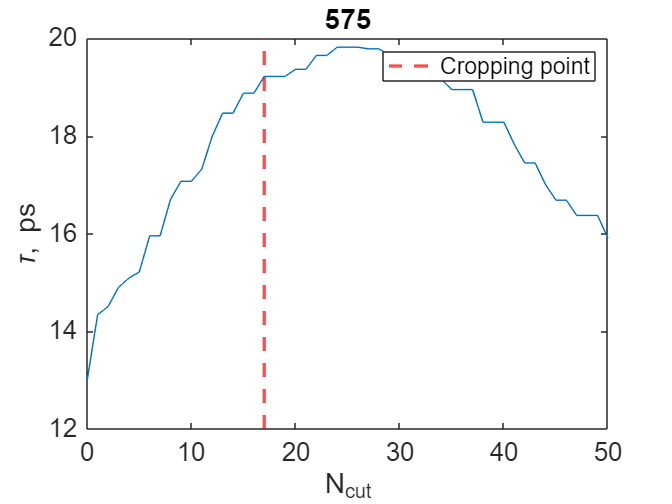

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:50
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 17;

a = 0:1:50;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 12;
tend = 26;
%tend = 26;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    4.401492825508100


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =   19.221498437275219


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

name = '575.png'

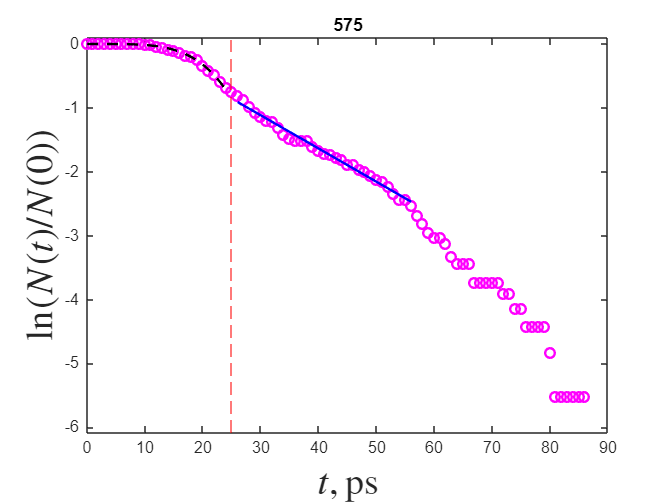

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

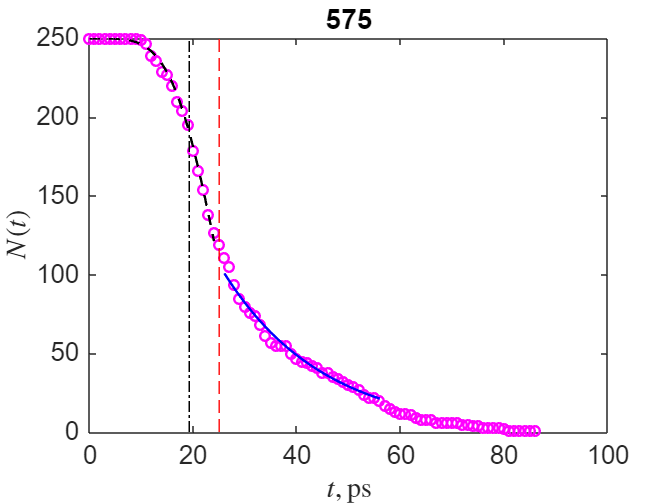


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 588

close all;clc;
format long
load forces_with_pbcatom
force=force588;
force_value = 588; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)

t =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 26;
tau_frac = 25;
%tau_frac = 50;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:50
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 6;

a = 0:1:50;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 12;
tend = 26;
%tend = 26;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

p =    2.916342474808897


**Параметры прямой для экспоненциального участка:**

%N_cut = %сколько обрезается!!

tau = tau_var(N_cut+1)

tau =   11.579513040709665


lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

name = '588.png'


plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)


% xlim2 = [0,140];
% ylim1 = [-6,0];
% xlim1 = [0,140];
% axs = [0.55 0.55 0.37 0.37];
% 
% two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)


tau_all = [tau_all, tau];
forces_all = [forces_all, force_value];

# 600

close all;clc;
format long
load forces_with_pbcatom
force=force600;

Unrecognized function or variable 'force600'.

force_value = 600; 
% Выборка без NaN и т.п.
ind=force(:,2)>0;
t=force(ind,1)
N=force(ind,2);

## Первый шаг - поиск классической экпоненциальной релаксации

% Время термализации

%tau_frac = 27;
tau_frac = 19;

Начальное значение:

N0=N(1);

Логарифм числа комплесков, деленый на начальное значение (фактически имеет смысл survival probability. см. ниже)

n=log(N/N0);

**ПОИСК МЕСТА ОБРЕЗАНИЯ**

pend_var = [];
tau_var = [];
lambda_var = [];

for N_cut = 0:70
    
t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

pend=polyfit(t_fit,n_fit,1);

pend_var = [pend_var; pend];


tau = 1/abs(pend(1));
lambda = pend(1);


tau_var = [tau_var; tau];
lambda_var = [lambda_var; lambda];

end

% N_cut обрезаем значит (N_cut+1)-ый элемент tau_var берём как tau
tau_var;

N_cut = 3;

a = 0:1:70;

figure
plot(a,tau_var)
hold on
vline = xline(N_cut,'--','color','red','Linewidth',2);
legend(vline,'Cropping point')
title(force_value)

%xlim([0,10])
%ylim([7000,1.3*10^4])

xlabel('N_{cut}')
ylabel('\tau, ps')
set(gca,'FontSize',16,'Fontname','Helvetica')

## Второй шаг - начальная неклассическая (дробная) релаксация

% ln(ln(N/N0)) 

t0 = 10;
%tend = 28;
tend = 20;

[p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend);

#### Параметры прямой для неэкспоненциального участка:

pinit;

#### **Степень дробно-экспоненциальной релаксации p:**

p

**Параметры прямой для экспоненциального участка:**

N_cut = 3; %сколько обрезается!!

tau = tau_var(N_cut+1)
lambda = lambda_var(N_cut+1);

Собирая это вместе, для графика в обычных и в полулогарифмических координатах:

ylim1 = [-3.3,1];
xlim2 = [0,2.2*10^4];

t_fit = [];
n_fit = [];
for i = 1:length(t)
    if N(i) > N_cut & t(i) > tau_frac
        t_fit = [t_fit; t(i)];
        n_fit = [n_fit; n(i)];
    end
end

plot_lnN(force_value,t,t_fit,n,tau_frac,pend_var(N_cut+1,1:2),pinit)

plot_N(force_value,t,t_fit,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit)

xlim2 = [0,140];
ylim1 = [-6,0];
xlim1 = [0,140];
axs = [0.55 0.55 0.37 0.37];
% 
two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend_var(N_cut+1,1:2),pinit,xlim1,ylim1,xlim2,axs)

forces_all = [forces_all, force_value]
tau_all = [tau_all, tau]

function [p,pinit] = plot_init_part_ln_ln(force_value,n,t,t0,tend)
%     figure
%     plot(log(t(t0:tend)),log(-n(t0:tend)),'o','color','magenta','LineWidth',1.5);
%     hold on
    pinit=polyfit(log(t(t0:tend)),log(-n(t0:tend)),1);
%     plot(log(t(t0:tend)),polyval(pinit,log(t(t0:tend))),'--','color','red','LineWidth',1.5);
%     xlabel('ln(t/ps)')
%     ylabel('ln(ln(N/N_0))')
%     set(gca,'FontSize',18)
%     title(force_value)
    
    p = pinit(1);
end

function plt_lnN = plot_lnN(force_value,t,t_fit,n,tau_frac,pend,pinit)

    figure
    plot(t,n,'o','color','magenta','LineWidth',1.5)
    hold on
    plot(t_fit,polyval(pend,t_fit),'color','blue','LineWidth',1.5)
    plot(t(t<tau_frac),-exp(polyval(pinit,log(t(t<tau_frac)))),'--','color','black','LineWidth',1.5)
    %xline(1/abs(pend(1)),'-.','color','black')
    xline(tau_frac,'--','color','red')
    %ylim(ylim1)
    ylim([1.1*min(n) 0.1])
    %set(gca,'FontSize',16,'FontName','Helvetica')
    xlabel('$$t, \mathrm{ps}$$','Interpreter','Latex','FontSize',24)
    ylabel('$$\ln(N(t)/N(0))$$','Interpreter','Latex','FontSize',24)
    title(force_value)
    name = [num2str(force_value),'.png']
    exportgraphics(gcf,name,'Resolution',300)


end

function plt_N = plot_N(force_value,t,t_fit,N,N0,tau_frac,pend,pinit)    
    %И в исходных переменных:
    
    figure
    plot(t,N,'o','color','magenta','LineWidth',1.5)
    hold on
    plot(t(t<tau_frac),N(1)*exp(-exp(pinit(2))*t(t<tau_frac).^(pinit(1))),'--','color','black','LineWidth',1.5)
    plot(t_fit,N0*exp(pend(2))*exp(pend(1)*t_fit),'color','blue','LineWidth',1.5)
    plot([1/abs(pend(1)) 1/abs(pend(1))],[0 N0],'-.','color','black')
    plot([tau_frac tau_frac],[0 N0],'--','color','red')
    %xlim(xlim2)
    xlabel('$$t, \mathrm{ps}$$','Interpreter','Latex','FontSize',14,'FontName','Helvetica') 
    ylabel('$$N(t)$$','Interpreter','Latex','FontSize',14,'FontName','Helvetica')
    set(gca,'FontSize',16,'Fontname','Helvetica')
    title(force_value)

end

function two_in_one = two_in_one(force_value,t,t_fit,n,N,N0,tau_frac,pend,pinit,xlim1,ylim1,xlim2,axs)

    figure
    box off
    plot(t,n,'o','color','magenta','LineWidth',1.5)
    hold on
    plot(t_fit,polyval(pend,t_fit),'color','blue','LineWidth',1.5)
    plot(t(t<tau_frac),-exp(polyval(pinit,log(t(t<tau_frac)))),'--','color','black','LineWidth',1.5)
    xlim(xlim1)
    ylim(ylim1)
    set(gca,'FontSize',12,'FontName','Helvetica','box','off')
    xlabel('$$t, \mathrm{ps}$$','Interpreter','Latex','FontSize',16)
    ylabel('$$\ln(N(t)/N(0))$$','Interpreter','Latex','FontSize',16)
    %title(force_value,'Fontsize',24)
    
    axes('Position',axs)
    box on
    plot(t,N,'o','color','magenta','LineWidth',1.5)
    hold on
    plot(t(t<tau_frac),N(1)*exp(-exp(pinit(2))*t(t<tau_frac).^(pinit(1))),'--','color','black','LineWidth',1.5)
    plot(t_fit,N0*exp(pend(2))*exp(pend(1)*t_fit),'color','blue','LineWidth',1.5)
    %plot([1/abs(pend(1)) 1/abs(pend(1))],[0 N0],'-.','color','red')
    plot([tau_frac tau_frac],[0 N0],'--','color','red')
    xlim(xlim2)
    xlabel('$$t, \mathrm{ps}$$','Interpreter','Latex','FontSize',14,'FontName','Helvetica') 
    ylabel('$$N(t)$$','Interpreter','Latex','FontSize',14,'FontName','Helvetica')
    %set(gca,'FontSize',12,'Fontname','Helvetica')
    
end